# LAB 1 ASSIGNMENTS:  

## 2.1 Position PID – control improvements

% load variables in workspace of LAB0 (parameters according to motor 8)
load params_inertial_case.mat
load PID_params_LAB0.mat
load params_estimated_LAB0.mat
sens.enc.pulse2deg = 360/2000; % in lab da cambiare in 360/4096
load LAB1_DATA_v7.mat % i dati si sovrascrivono ATTENZIONE!
load LAB1_DATA_V9.mat
load totdata.mat

### 2.1.1 Anti wind-up:

% open simulink model
open_system('Antiwindup_sim.slx');
set_param('Antiwindup_sim', 'SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

step_size = 360;
ctrl.Kw = 0;

% run simulation no antiwindup
sim('Antiwindup_sim');
simdata.noawu.t        = MotorData.time;
simdata.noawu.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
simdata.noawu.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.noawu.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.noawu.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
%simdata.noawu.u        = MotorData.signals(4).values;          % control input  [V]
simdata.sat.noawu.t = PID_data.time;
simdata.sat.noawu.nosat = PID_data.signals(1).values;
simdata.sat.noawu.sat = PID_data.signals(2).values;

ctrl.Kw = 5/ctrl.ts5;   % 20 

% run simulation
sim('Antiwindup_sim');
simdata.awu.t        = MotorData.time;
simdata.awu.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
simdata.awu.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.awu.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.awu.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
%simdata.awu.u        = MotorData.signals(4).values;          % control input  [V]
simdata.sat.awu.t = PID_data.time;
simdata.sat.awu.nosat = PID_data.signals(1).values;
simdata.sat.awu.sat = PID_data.signals(2).values;

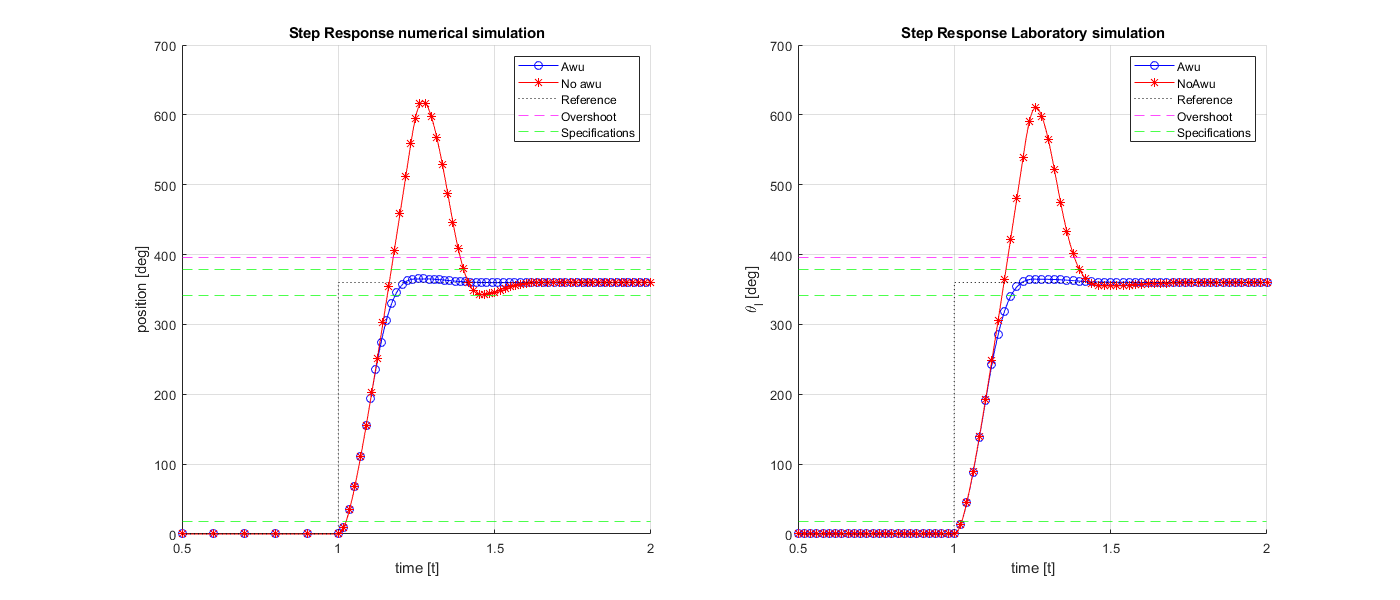

figure('Renderer', 'painters', 'Position', [10 10 1400 600])
subplot(1,2,1)
hold on;
plot(simdata.awu.t,simdata.awu.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.awu.thl_meas));
plot(simdata.noawu.t,simdata.noawu.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.noawu.thl_meas));
plot(simdata.awu.t,simdata.awu.thl_ref,'k:');
title('Step Response numerical simulation')
xlabel('time [t]');
ylabel('position [deg]');
grid on;
hold on;
yline(step_size*1.1,'m--')
yline(step_size*1.05,'g--')
yline(step_size*0.95,'g--')
yline(step_size*0.05,'g--')
hold off;
xlim([0.5 2])
ylim([0 700])
legend('Awu','No awu', 'Reference','Overshoot','Specifications')
%Practise
subplot(1,2,2)
hold on;
plot(data.awu.t,data.awu.thl_meas,'b-o','MarkerIndices',1:20:length(data.awu.thl_meas));
plot(data.noawu.t,data.noawu.thl_meas,'r-*','MarkerIndices',1:20:length(data.noawu.thl_meas));
plot(data.awu.t,data.awu.thl_ref,'k:');
title('Step Response Laboratory simulation')
xlabel('time [t]');
ylabel('\theta_l [deg]');
grid on;
hold on;
yline(step_size*1.1,'m--')
yline(step_size*1.05,'g--')
yline(step_size*0.95,'g--')
yline(step_size*0.05,'g--')
hold off;
xlim([0.5 2])
ylim([0 700])
legend('Awu','NoAwu', 'Reference','Overshoot','Specifications')

simdata.noawu.stepinfo = stepinfo(simdata.noawu.thl_meas,simdata.noawu.t,'SettlingTimeThreshold',0.05);
simdata.awu.stepinfo   = stepinfo(simdata.awu.thl_meas,simdata.awu.t,'SettlingTimeThreshold',0.05);
stepinfo(simdata.noawu.thl_meas,simdata.noawu.t,'SettlingTimeThreshold',0.05)

ans = struct with fields:
        RiseTime: 0.1141
    SettlingTime: 1.4012
     SettlingMin: 324.4491
     SettlingMax: 619.2912
       Overshoot: 72.0467
      Undershoot: 2.4195e-26
            Peak: 619.2912
        PeakTime: 1.2702


stepinfo(simdata.awu.thl_meas,simdata.awu.t,'SettlingTimeThreshold',0.05)

ans = struct with fields:
        RiseTime: 0.1296
    SettlingTime: 1.1823
     SettlingMin: 324.1268
     SettlingMax: 365.0654
       Overshoot: 1.3756
      Undershoot: 2.4184e-26
            Peak: 365.0654
        PeakTime: 1.2480


ctrl.Kw = 5/ctrl.ts5;   % 33.3

% run simulation
sim('Antiwindup_sim');
simdata.awu1.t        = MotorData.time;
simdata.awu1.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
simdata.awu1.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.awu1.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.awu1.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
%simdata.awu1.u        = MotorData.signals(4).values;          % control input  [V]
simdata.sat.awu1.t = PID_data.time;
simdata.sat.awu1.nosat = PID_data.signals(1).values;
simdata.sat.awu1.sat = PID_data.signals(2).values;

ctrl.Kw = 25;   % 20 

% run simulation
sim('Antiwindup_sim');
simdata.awu2.t        = MotorData.time;
simdata.awu2.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
simdata.awu2.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.awu2.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.awu2.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
%simdata.awu2.u        = MotorData.signals(4).values;          % control input  [V]
simdata.sat.awu2.t = PID_data.time;
simdata.sat.awu2.nosat = PID_data.signals(1).values;
simdata.sat.awu2.sat = PID_data.signals(2).values;

ctrl.Kw = 50;   % 20 

% run simulation
sim('Antiwindup_sim');
simdata.awu3.t        = MotorData.time;
simdata.awu3.thl_ref  = MotorData.signals(1).values(:,1);     % reference input [deg]
simdata.awu3.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.awu3.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.awu3.acc_meas = MotorData.signals(3).values;          % acc measured [rpm/s]
%simdata.awu3.u        = MotorData.signals(4).values;          % control input  [V]
simdata.sat.awu3.t = PID_data.time;
simdata.sat.awu3.nosat = PID_data.signals(1).values;
simdata.sat.awu3.sat = PID_data.signals(2).values;

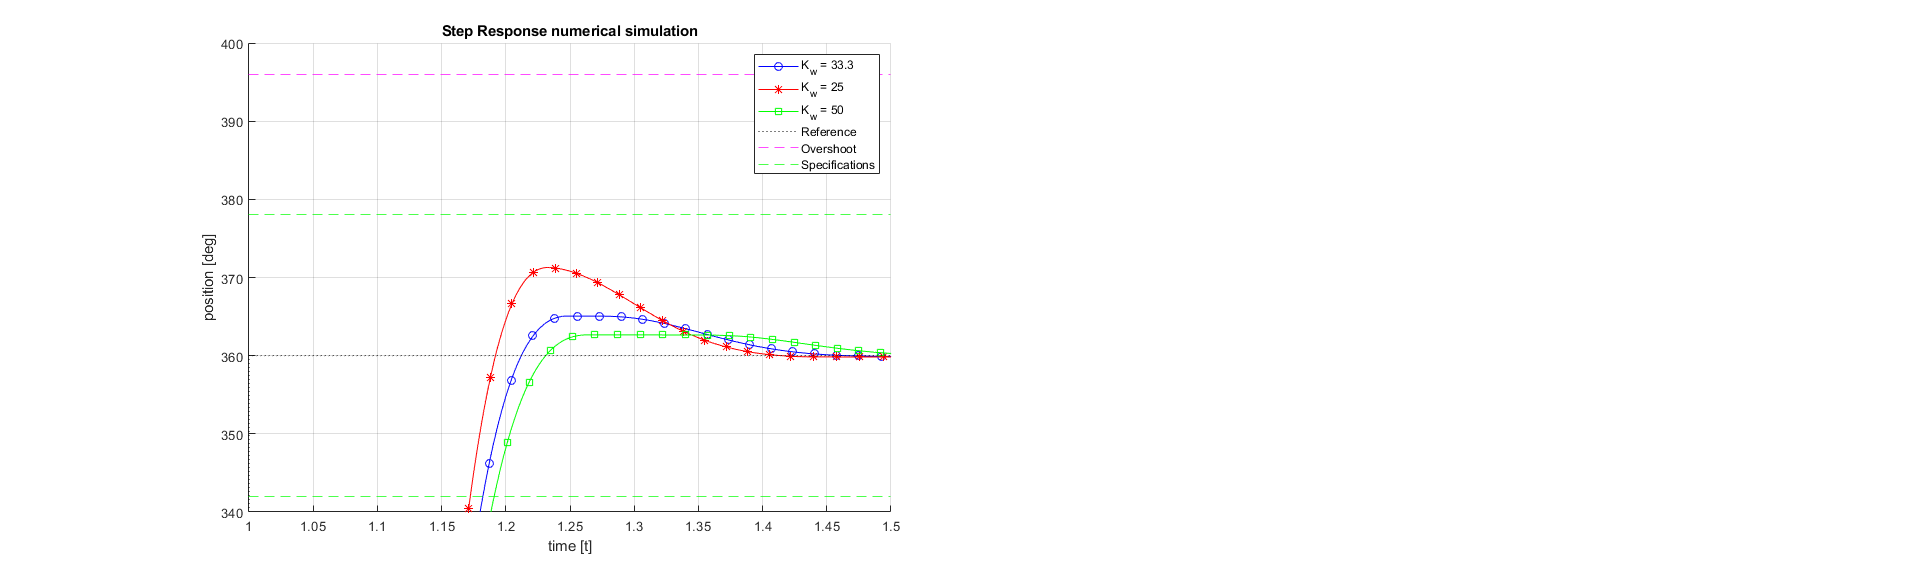

figure('Renderer', 'painters', 'Position', [10 10 2000 600])
subplot(1,2,1)
hold on;
plot(simdata.awu1.t,simdata.awu1.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.awu1.thl_meas));
plot(simdata.awu2.t,simdata.awu2.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.awu2.thl_meas));
plot(simdata.awu3.t,simdata.awu3.thl_meas,'g-s','MarkerIndices',1:100:length(simdata.awu3.thl_meas));
plot(simdata.awu.t,simdata.awu.thl_ref,'k:');
title('Step Response numerical simulation')
xlabel('time [t]');
ylabel('position [deg]');
grid on;
hold on;
yline(step_size*1.1,'m--')
yline(step_size*1.05,'g--')
yline(step_size*0.95,'g--')
yline(step_size*0.05,'g--')
hold off;
xlim([1 1.5])
ylim([340 400])
legend('K_w = 33.3','K_w = 25','K_w = 50', 'Reference','Overshoot','Specifications')

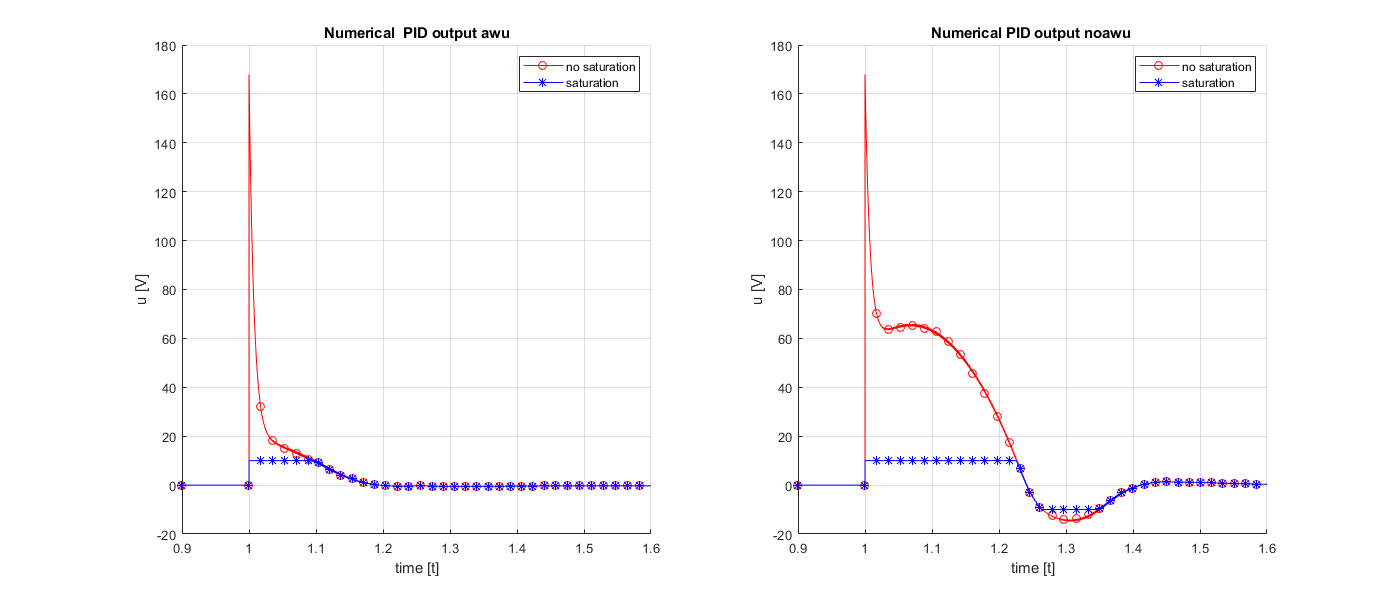

%saturation in simulation
figure('Renderer', 'painters', 'Position', [10 10 1400 600])
subplot(1,2,1)
hold on;
plot(simdata.sat.awu.t,simdata.sat.awu.nosat,'r-o','MarkerIndices',1:100:length(simdata.sat.awu.nosat));
plot(simdata.sat.awu.t,simdata.sat.awu.sat,'b-*','MarkerIndices',1:100:length(simdata.sat.awu.sat));
title('Numerical  PID output awu')
xlabel('time [t]');
ylabel('u [V]');
grid on;
hold on;
xlim([0.9 1.6])
legend ('no saturation','saturation');
hold off;
subplot(1,2,2)
hold on;
plot(simdata.sat.noawu.t,simdata.sat.noawu.nosat,'r-o','MarkerIndices',1:100:length(simdata.sat.noawu.nosat));
plot(simdata.sat.noawu.t,simdata.sat.noawu.sat,'b-*','MarkerIndices',1:100:length(simdata.sat.noawu.sat));
title('Numerical PID output noawu ')
xlabel('time [t]');
ylabel('u [V]');
grid on;
hold on;
xlim([0.9 1.6])
legend ('no saturation','saturation');
hold off;

## 2.1.3 Feed-forward:

% open simulink model
open_system('Feedforward_antiwindup_sim.slx');
set_param('Feedforward_antiwindup_sim','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

Filters:

fltr.wc = 2*pi*20;            % was 2*pi*50
ctrl.Kw = 0;
% define speed filter
Hws = tf([fltr.wc^2,0],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHws, denHws] = tfdata(Hws,'v');

% define current filter
Hwsi =  tf([fltr.wc^2],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHwsi, denHwsi] = tfdata(Hwsi,'v');

% define acc filter
Hwa = tf([fltr.wc^2,0],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHwa, denHwa] = tfdata(Hwa,'v');

FeedForward parameters:

% Feedforward params
inertia_comp = gbox.N*Req*Jeq_hat /(drv.dcgain*mot.Kt);
friction_comp = Req/(drv.dcgain*mot.Kt*gbox.N);
BEMF_comp = gbox.N*mot.Ke/drv.dcgain;  

% SIMULATION WITHOUT FEEDFORWARD
sim('Feedforward_antiwindup_sim');
simdata.noff.t        = MotorData.time;
simdata.noff.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
simdata.noff.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.noff.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
simdata.noff.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
simdata.noff.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
simdata.noff.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
%simdata.noff.u       = MotorData.signals(4).values;          % control input  [V]
simdata.noff.errorT = MotorData.signals(4).values;

% SIMULATION WITH FEEDFORWARD
sim('Feedforward_antiwindup_sim');
simdata.ff.t        = MotorData.time;
simdata.ff.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
simdata.ff.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
simdata.ff.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
simdata.ff.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
simdata.ff.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
simdata.ff.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
%simdata.ff.u        = MotorData.signals(4).values;          % control input  [V]
simdata.ff.errorT = MotorData.signals(4).values;

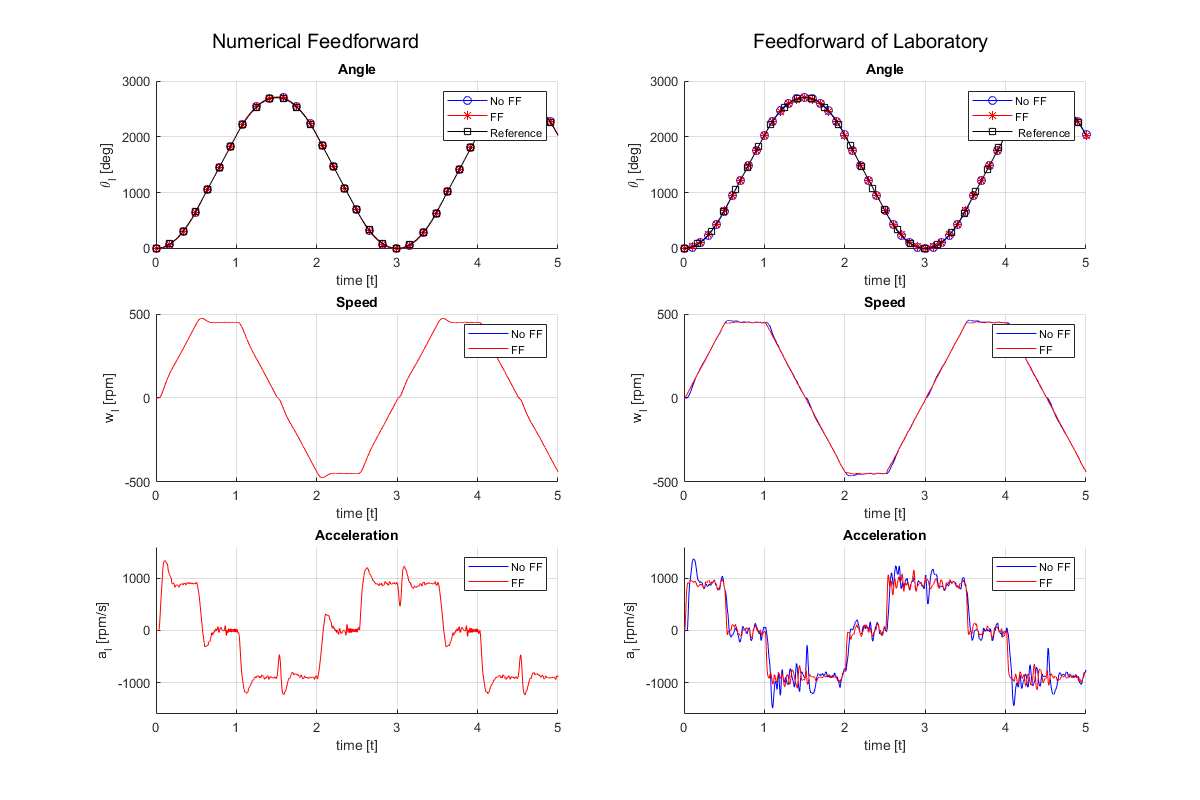

%SIMULATION
figure('Renderer', 'painters', 'Position', [10 10 1200 800])
subplot(3,2,1);
hold on
plot(simdata.noff.t,simdata.noff.thl_meas,'b-o','MarkerIndices',1:1000:length(simdata.ff.thl_meas));
plot(simdata.ff.t,simdata.ff.thl_meas,'r-*','MarkerIndices',1:1000:length(simdata.ff.thl_meas));
plot(simdata.noff.t,simdata.noff.thl_ref ,'k-s','MarkerIndices',1:1000:length(simdata.noff.thl_meas));
hold off
grid on;
title('Angle')
xlabel('time [t]');
ylabel('\theta_{l} [deg]');
legend('No FF','FF','Reference');
xlim([0 5])

subplot(3,2,3);
hold on
plot(simdata.noff.t,simdata.noff.wl_meas,'b');
plot(simdata.ff.t,simdata.ff.wl_meas,'r');
hold off
title('Speed')
grid on;
xlabel('time [t]');
ylabel('w_{l} [rpm]');
xlim([0 5])
legend('No FF','FF');


subplot(3,2,5);
hold on
plot(simdata.noff.t,simdata.noff.acc_meas,'b');
plot(simdata.ff.t,simdata.ff.acc_meas,'r');
hold off;
title('Acceleration')
grid on;
xlabel('time [t]');
ylabel('a_{l} [rpm/s]');
legend('No FF','FF');
xlim([0 5])
ylim([-1600 1600])

%PRACTICE
subplot(3,2,2);
hold on
plot(data.noff.t,data.noff.thl_meas,'b-o','MarkerIndices',1:100:length(data.ff.thl_meas));
plot(data.ff.t,data.ff.thl_meas,'r-*','MarkerIndices',1:100:length(data.ff.thl_meas));
plot(simdata.noff.t,simdata.noff.thl_ref ,'k-s','MarkerIndices',1:1000:length(simdata.noff.thl_meas));
hold off;
title('Angle')
grid on;
xlabel('time [t]');
ylabel('\theta_{l} [deg]');
legend('No FF','FF',' Reference');
xlim([0 5])

subplot(3,2,4);
hold on
plot(data.noff.t,data.noff.wl_meas,'b');
plot(data.ff.t,data.ff.wl_meas,'r');
hold off;
title('Speed')
grid on;
xlabel('time [t]');
ylabel('w_l [rpm]');
xlim([0 5])
legend('No FF','FF');

subplot(3,2,6);
hold on;
plot(data.noff.t,data.noff.acc_meas,'b');
plot(data.ff.t,data.ff.acc_meas,'r');
title('Acceleration')
grid on;
xlabel('time [t]');
ylabel('a_{l} [rpm/s]');
legend('No FF','FF');
xlim([0 5])
ylim([-1600 1600])

sgtitle('Numerical Feedforward                                                            Feedforward of Laboratory') 
hold off;

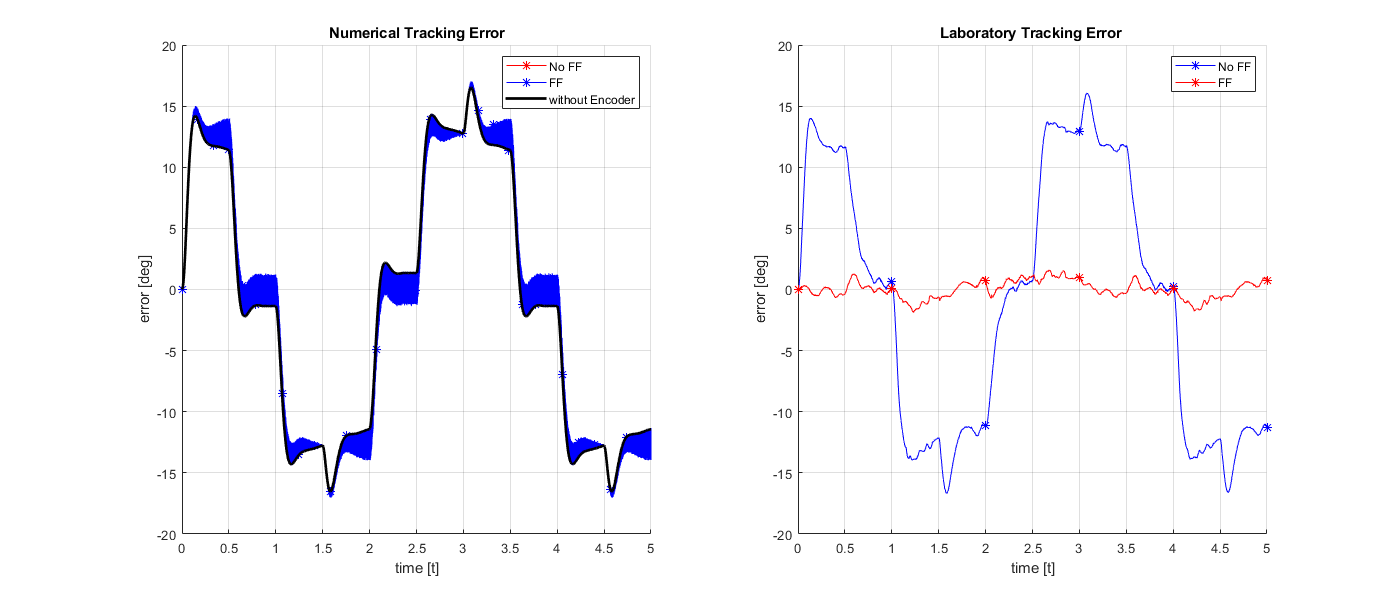

%tracking error plot
simdata.noff.error = simdata.noff.thl_ref - simdata.noff.thl_meas;
simdata.ff.error = simdata.ff.thl_ref - simdata.ff.thl_meas;
data.noff.errorT = data.noff.thl_ref - data.noff.thl_meas;
data.ff.errorT = data.ff.thl_ref - data.ff.thl_meas;
%SIMULATION
figure('Renderer', 'painters', 'Position', [10 10 1400 600])
subplot(1,2,1);
hold on
plot(simdata.ff.t,simdata.ff.errorT,'r-*','MarkerIndices',1:1000:length(simdata.ff.errorT));
plot(simdata.noff.t,simdata.noff.errorT,'b-*','MarkerIndices',1:1000:length(simdata.noff.errorT));
plot(simdata.noff.t,simdata.noff.error,'k','MarkerIndices',1:1000:length(simdata.noff.error),"LineWidth",2);
plot(simdata.ff.t,simdata.ff.error,'k','MarkerIndices',1:1000:length(simdata.ff.error),"LineWidth",2);
hold off
grid on;
title('Numerical Tracking Error')
xlabel('time [t]');
ylabel('error [deg]');
legend('No FF','FF','without Encoder');
xlim([0 5])

subplot(1,2,2);
hold on
plot(data.noff.t,data.noff.errorT,'b-*','MarkerIndices',1:1000:length(data.noff.errorT));
plot(data.ff.t,data.ff.errorT,'r-*','MarkerIndices',1:1000:length(data.ff.errorT));
hold off
grid on;
title('Laboratory Tracking Error ')
xlabel('time [t]');
ylabel('error [deg]');
legend('No FF','FF');
xlim([0 5])

% hold on
% plot(simdata.noff.t,simdata.noff.wl_meas,'b');
% plot(simdata.ff.t,simdata.ff.wl_meas,'r');
% hold off
% title('Speed')
% grid on;
% xlabel('time [t]');
% ylabel('w_{l} [rpm]');
% xlim([0 5])
% legend('No FF','FF');

## 2.2 State-space control design

% load variables in workspace of LAB0 (parameters according to motor 8)
load params_inertial_case.mat
load params_estimated_LAB0.mat
load PID_params_LAB0.mat

Beq = Beq_hat;                           % mot.B + mld.B/gbox.N^2;    
Jeq = Jeq_hat;
model.km = (drv.dcgain*mot.Kt)/(Req*Beq + mot.Kt*mot.Ke);
model.Tm = (Req*Jeq)/(Req*Beq + mot.Kt*mot.Ke);
sens.enc.pulse2deg = 360/2000; % in lab da cambiare in 360/4096

%   non-encapsulated SS data
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;

%   SS data encapulated in a SS object
sys = ss(A, B, C, D);

### 2.2.1 Nominal Tracking Design

%compute N_x, N_u
S = [A,B;C,0];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

% define H1 filter
H1.wc = 2*pi*50;   
H1.d = 1/sqrt(2);
H1s = tf([H1.wc^2,0],[1, 2*H1.d*H1.wc, H1.wc^2]);
[numH1, denH1] = tfdata(H1s,'v');

%specs
spec.ts5    = 0.15;         % Settling-time
spec.Mp     = 0.1;          % Overshoot
spec.damp   = log(1/spec.Mp) / (sqrt(pi^2+(log(1/spec.Mp))^2));
spec.wn   = 3 / (spec.damp*spec.ts5);

%poles to place
Ts = tf([spec.wn^2],[1, 2*spec.damp*spec.wn,spec.wn^2]);
p=pole(Ts);

%Compute feedback matrix
K=place(A,B,p);

### 2.2.2

% open simulink model
open_system('nominal_tracking.slx');
set_param('nominal_tracking','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

%with static friction
step_size = 40;
sim('nominal_tracking');

simdata.nominal.step1.t    = MotorData.time;
simdata.nominal.step1.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.nominal.step1.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg] 
simdata.nominal.step1.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.nominal.step1.u        = MotorData.signals(3).values;          % control input [V]

step_size = 70;
sim('nominal_tracking');

simdata.nominal.step2.t        = MotorData.time;                       % reference angle input [deg]
simdata.nominal.step2.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.nominal.step2.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.nominal.step2.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.nominal.step2.u        = MotorData.signals(3).values;          % control input [V]

step_size = 120;
sim('nominal_tracking');

simdata.nominal.step3.t        = MotorData.time;                       % reference angle input [deg]
simdata.nominal.step3.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.nominal.step3.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.nominal.step3.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.nominal.step3.u        = MotorData.signals(3).values;          % control input [V]

%without static friction
step_size = 40;
sim('nominal_tracking');

simdata.nominal.step1.nsf.t    = MotorData.time;
simdata.nominal.step1.nsf.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.nominal.step1.nsf.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg] 
simdata.nominal.step1.nsf.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.nominal.step1.u        = MotorData.signals(3).values;          % control input [V]

step_size = 70;
sim('nominal_tracking');

simdata.nominal.step2.nsf.t        = MotorData.time;                       % reference angle input [deg]
simdata.nominal.step2.nsf.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.nominal.step2.nsf.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.nominal.step2.nsf.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.nominal.step2.nsf.u        = MotorData.signals(3).values;          % control input [V]

step_size = 120;
sim('nominal_tracking');

simdata.nominal.step3.nsf.t        = MotorData.time;                       % reference angle input [deg]
simdata.nominal.step3.nsf.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.nominal.step3.nsf.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.nominal.step3.nsf.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.nominal.step3.u        = MotorData.signals(3).values;          % control input [V]

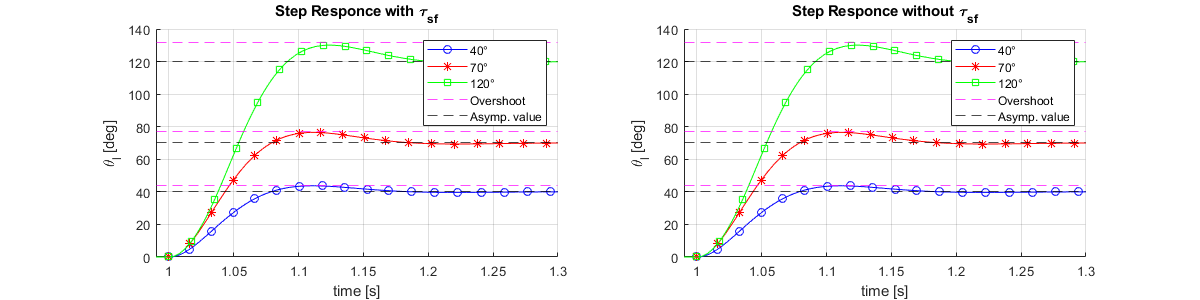

%SIMULATION static friction
figure('Renderer', 'painters', 'Position', [10 10 1200 300])

subplot(1,2,1);
hold on;
plot(simdata.nominal.step1.t,simdata.nominal.step1.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.nominal.step1.t));
plot(simdata.nominal.step2.t,simdata.nominal.step2.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.nominal.step2.t));
plot(simdata.nominal.step3.t,simdata.nominal.step3.thl_meas,'g-s','MarkerIndices',1:100:length(simdata.nominal.step3.t));
yline(step_size*1.1,'m--')
yline(40,'k--')
yline(70,'k--')
yline(120,'k--')
yline(40*1.1,'m--')
yline(70*1.1,'m--')
hold off;
title('Step Responce with \tau_{sf}')
legend('40°','70°','120°','Overshoot','Asymp. value');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
xlim([0.99 1.3])
ylim([0 140])

subplot(1,2,2);
hold on;
plot(simdata.nominal.step1.nsf.t,simdata.nominal.step1.nsf.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.nominal.step1.nsf.t));
plot(simdata.nominal.step2.nsf.t,simdata.nominal.step2.nsf.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.nominal.step2.nsf.t));
plot(simdata.nominal.step3.nsf.t,simdata.nominal.step3.nsf.thl_meas,'g-s','MarkerIndices',1:100:length(simdata.nominal.step3.nsf.t));
yline(step_size*1.1,'m--')
yline(40,'k--')
yline(70,'k--')
yline(120,'k--')
yline(40*1.1,'m--')
yline(70*1.1,'m--')
hold off;
title('Step Responce without \tau_{sf}')
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
legend('40°','70°','120°','Overshoot','Asymp. value');
xlim([0.99 1.3])
ylim([0 140])
grid on

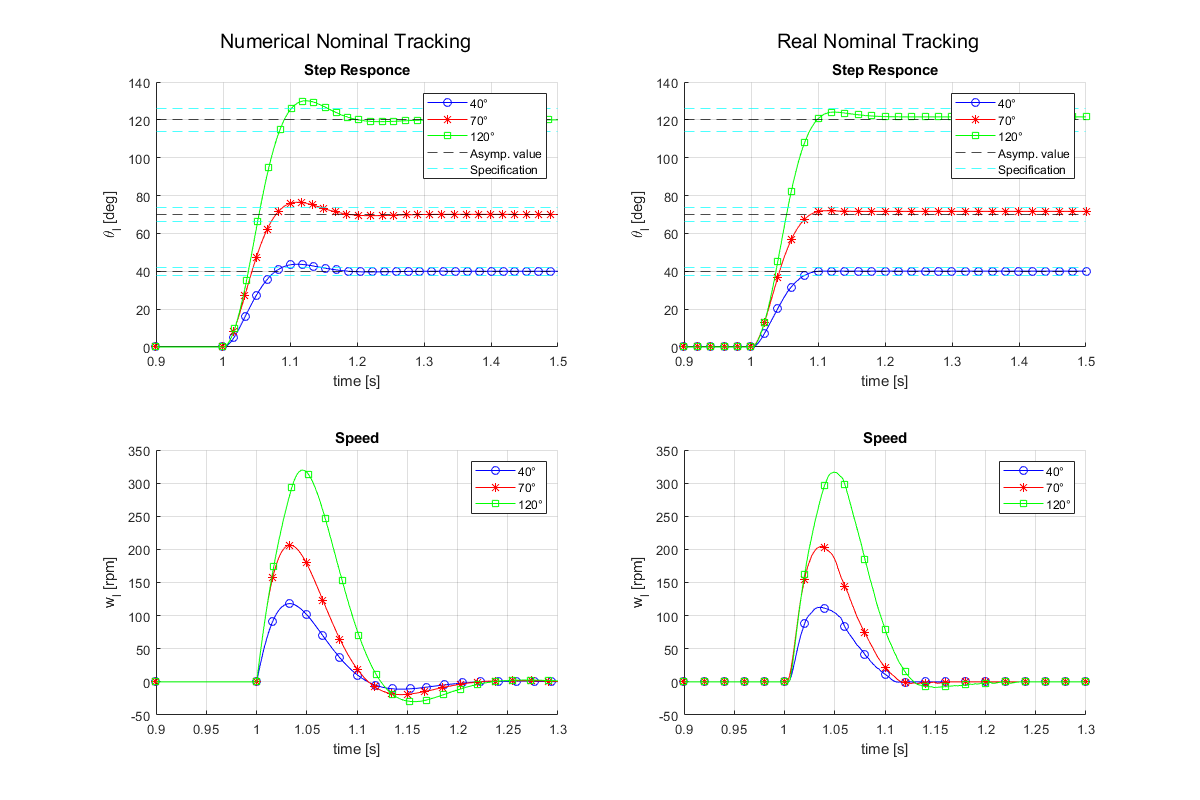

%SIMULATION
figure('Renderer', 'painters', 'Position', [10 10 1200 800])

subplot(2,2,1);
hold on;
plot(simdata.nominal.step1.t,simdata.nominal.step1.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.nominal.step1.t));
plot(simdata.nominal.step2.t,simdata.nominal.step2.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.nominal.step2.t));
plot(simdata.nominal.step3.t,simdata.nominal.step3.thl_meas,'g-s','MarkerIndices',1:100:length(simdata.nominal.step3.t));
yline(40,'k--')
yline(40*1.05,'c--')
yline(70,'k--')
yline(120,'k--')
yline(40*0.95,'c--')
yline(70*1.05,'c--')
yline(70*0.95,'c--')
yline(120*1.05,'c--')
yline(120*0.95,'c--')
hold off;
title('Step Responce')
legend('40°','70°','120°','Asymp. value','Specification');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
xlim([0.9,1.5]);
ylim([0 140])

subplot(2,2,3);
hold on;
plot(simdata.nominal.step1.t,simdata.nominal.step1.wl_meas,'b-o','MarkerIndices',1:100:length(simdata.nominal.step1.t));
plot(simdata.nominal.step2.t,simdata.nominal.step2.wl_meas,'r-*','MarkerIndices',1:100:length(simdata.nominal.step2.t));
plot(simdata.nominal.step3.t,simdata.nominal.step3.wl_meas,'g-s','MarkerIndices',1:100:length(simdata.nominal.step3.t));
hold off;
title('Speed')
xlabel('time [s]');
ylabel('w_{l} [rpm]');
legend('40°','70°','120°');
grid on
xlim([0.9,1.3]);

%PRACTICE
subplot(2,2,2);
hold on;
plot(data.nominal.step1.t,data.nominal.step1.thl_meas,'b-o','MarkerIndices',1:20:length(data.nominal.step1.t));
plot(data.nominal.step2.t,data.nominal.step2.thl_meas,'r-*','MarkerIndices',1:20:length(data.nominal.step2.t));
plot(data.nominal.step3.t,data.nominal.step3.thl_meas,'g-s','MarkerIndices',1:20:length(data.nominal.step3.t));
title('Step Responce')
yline(40,'k--')
yline(40*1.05,'c--')
yline(70,'k--')
yline(120,'k--')
yline(40*0.95,'c--')
yline(70*1.05,'c--')
yline(70*0.95,'c--')
yline(120*1.05,'c--')
yline(120*0.95,'c--')
hold off;
legend('40°','70°','120°','Asymp. value','Specification');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
xlim([0.9,1.5]);
ylim([0 140])

subplot(2,2,4);
hold on;
plot(data.nominal.step1.t,data.nominal.step1.wl_meas,'b-o','MarkerIndices',1:20:length(data.nominal.step1.t));
plot(data.nominal.step2.t,data.nominal.step2.wl_meas,'r-*','MarkerIndices',1:20:length(data.nominal.step2.t));
plot(data.nominal.step3.t,data.nominal.step3.wl_meas,'g-s','MarkerIndices',1:20:length(data.nominal.step3.t));
hold off;
title('Speed')
xlabel('time [s]');
ylabel('w_{l} [rpm]');
legend('40°','70°','120°');
grid on
xlim([0.9,1.3]);
sgtitle('Numerical Nominal Tracking                                                       Real Nominal Tracking') 

### 2.2.3 Robust Tracking Design

% open simulink model (we added the antiwindup component)
open_system('robust_tracking_integral.slx');
set_param('robust_tracking_integral','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');
ctrl.Kw = 0;%5/ctrl.ts5;   % 20

%poles
sigma=-spec.damp*spec.wn;
omega_d=spec.wn*sqrt(1-spec.damp^2);

p1 = [sigma+omega_d*j , sigma-omega_d*j , sigma ];
p2 = [sigma , sigma , sigma ];
p3 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 2*sigma ];
p4 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 3*sigma ];

%space model with augmented state
zer = zeros(2,1);
Ae=[0 C; zer A];
Be=[0; B];
Ce=[0 C];

step_size=40;
ctrl.Kw = 5/ctrl.ts5;

%1st pole
Ke = acker(Ae,Be,p1);
K2 = [Ke(2) Ke(3)];
Ki = Ke(1);
sim('robust_tracking_integral');
simdata.robust.step1.p1.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step1.p1.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step1.p1.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step1.p1.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step1.p1.u        = MotorData.signals(3).values;          % control input [V]
simdata.robust.step1.p1.u_nosat  = ControllerData.signals(1).values;     % PID no sat
simdata.robust.step1.p1.u_sat    = ControllerData.signals(2).values;     % PID  sat

%2nd pole
Ke = acker(Ae,Be,p2);
Ki = Ke(1);
K2 = [Ke(2) Ke(3)];
sim('robust_tracking_integral');
simdata.robust.step1.p2.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step1.p2.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step1.p2.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step1.p2.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step1.p2.u        = MotorData.signals(3).values;          % control input [V]
simdata.robust.step1.p2.u_nosat  = ControllerData.signals(1).values;     % PID no sat
simdata.robust.step1.p2.u_sat    = ControllerData.signals(2).values;     % PID  sat

%3rd pole
Ke = acker(Ae,Be,p3);
Ki = Ke(1);
K2 = [Ke(2) Ke(3)];
sim('robust_tracking_integral');
simdata.robust.step1.p3.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step1.p3.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step1.p3.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step1.p3.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step1.p3.u        = MotorData.signals(3).values;          % control input [V]
simdata.robust.step1.p3.u_nosat  = ControllerData.signals(1).values;     % PID no sat
simdata.robust.step1.p3.u_sat    = ControllerData.signals(2).values;     % PID  sat

%4th pole
Ke = acker(Ae,Be,p4);
Ki = Ke(1);
K2 = [Ke(2) Ke(3)];
sim('robust_tracking_integral');
simdata.robust.step1.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step1.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step1.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step1.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step1.p4.u        = MotorData.signals(3).values;          % control input [V]
simdata.robust.step1.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
simdata.robust.step1.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat

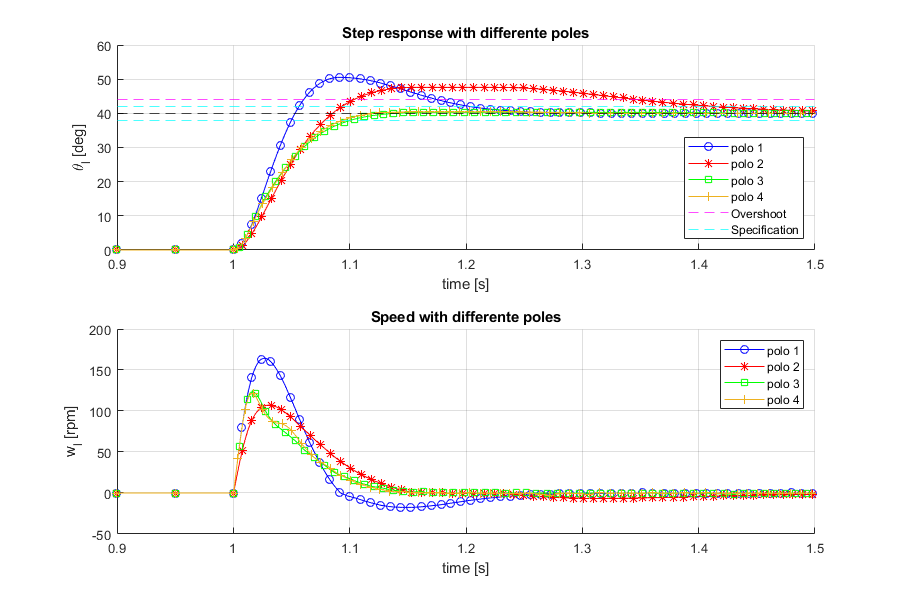

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2,1,1);
hold on;
plot(simdata.robust.step1.p1.t ,simdata.robust.step1.p1.thl_meas,'b-o','MarkerIndices',1:50:length(simdata.robust.step1.p1.t));
plot(simdata.robust.step1.p2.t ,simdata.robust.step1.p2.thl_meas,'r-*','MarkerIndices',1:50:length(simdata.robust.step1.p2.t));
plot(simdata.robust.step1.p3.t ,simdata.robust.step1.p3.thl_meas,'g-s','MarkerIndices',1:50:length(simdata.robust.step1.p3.t));
plot(simdata.robust.step1.p4.t ,simdata.robust.step1.p4.thl_meas,'-+','Color','#EDB120','MarkerIndices',1:50:length(simdata.robust.step1.p4.t));
yline(40*1.1,'m--')
yline(40*1.05,'c--')
yline(40*0.95,'c--')
yline(40,'k--')
hold off;
legend('polo 1','polo 2','polo 3','polo 4','Overshoot','Specification','Location','southeast');
ylabel('\theta_{l} [deg]');
xlabel('time [s]');
grid on
xlim([0.9,1.5]);
title('Step response with differente poles')

subplot(2,1,2);
hold on;
plot(simdata.robust.step1.p1.t ,simdata.robust.step1.p1.wl_meas,'b-o','MarkerIndices',1:50:length(simdata.robust.step1.p1.t));
plot(simdata.robust.step1.p2.t ,simdata.robust.step1.p2.wl_meas,'r-*','MarkerIndices',1:50:length(simdata.robust.step1.p2.t));
plot(simdata.robust.step1.p3.t ,simdata.robust.step1.p3.wl_meas,'g-s','MarkerIndices',1:50:length(simdata.robust.step1.p3.t));
plot(simdata.robust.step1.p4.t ,simdata.robust.step1.p4.wl_meas,'-+','Color','#EDB120','MarkerIndices',1:50:length(simdata.robust.step1.p4.t));
hold off;
ylabel('w_{l} [rpm]');
xlabel('time [s]');
legend('polo 1','polo 2','polo 3','polo 4')
grid on
xlim([0.9,1.5])
title('Speed with differente poles')

S1 = stepinfo(simdata.robust.step1.p1.thl_meas,simdata.robust.step1.p1.t,"SettlingTimeThreshold",0.05)

S1 = struct with fields:
        RiseTime: 0.0360
    SettlingTime: 1.2016
     SettlingMin: 36.0975
     SettlingMax: 50.5331
       Overshoot: 26.0438
      Undershoot: 2.1723e-25
            Peak: 50.5331
        PeakTime: 1.0922


S2 = stepinfo(simdata.robust.step1.p2.thl_meas,simdata.robust.step1.p2.t,"SettlingTimeThreshold",0.05)

S2 = struct with fields:
        RiseTime: 0.0582
    SettlingTime: 1.4183
     SettlingMin: 35.9486
     SettlingMax: 47.5867
       Overshoot: 19.2463
      Undershoot: 1.6801e-06
            Peak: 47.5867
        PeakTime: 1.1844


S3 = stepinfo(simdata.robust.step1.p3.thl_meas,simdata.robust.step1.p3.t,"SettlingTimeThreshold",0.05)

S3 = struct with fields:
        RiseTime: 0.0743
    SettlingTime: 1.1015
     SettlingMin: 36.0446
     SettlingMax: 40.2897
       Overshoot: 0.6019
      Undershoot: 9.1704e-07
            Peak: 40.2897
        PeakTime: 1.2607


S4 = stepinfo(simdata.robust.step1.p4.thl_meas,simdata.robust.step1.p4.t,"SettlingTimeThreshold",0.05)

S4 = struct with fields:
        RiseTime: 0.0698
    SettlingTime: 1.0938
     SettlingMin: 35.9680
     SettlingMax: 40.4454
       Overshoot: 1.2293
      Undershoot: 8.6245e-07
            Peak: 40.4454
        PeakTime: 1.1869


### 2.2.4

% select p2 (it is the best) and confront in practice
Ke = acker(Ae,Be,p4);
Ki = Ke(1);
K2 = [Ke(2) Ke(3)];
ctrl.Kw = 5/ctrl.ts5;

step_size = 40;

%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.step1.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step1.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step1.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step1.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step1.p4.u        = MotorData.signals(3).values;          % control input [V]
%simdata.robust.step1.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
%simdata.robust.step1.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


%No static friction

%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.step1.nsf.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step1.nsf.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step1.nsf.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step1.nsf.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step1.nsf.p4.u        = MotorData.signals(3).values;          % control input [V]
%simdata.robust.step1.nsf.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
%simdata.robust.step1.nsf.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


step_size = 70;

%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.step2.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step2.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step2.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step2.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step2.p4.u        = MotorData.signals(3).values;          % control input [V]
%simdata.robust.step2.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
%simdata.robust.step2.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


step_size = 120;

%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.step3.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.step3.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.step3.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.step3.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.step3.p4.u        = MotorData.signals(3).values;          % control input [V]
%simdata.robust.step3.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
%simdata.robust.step3.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


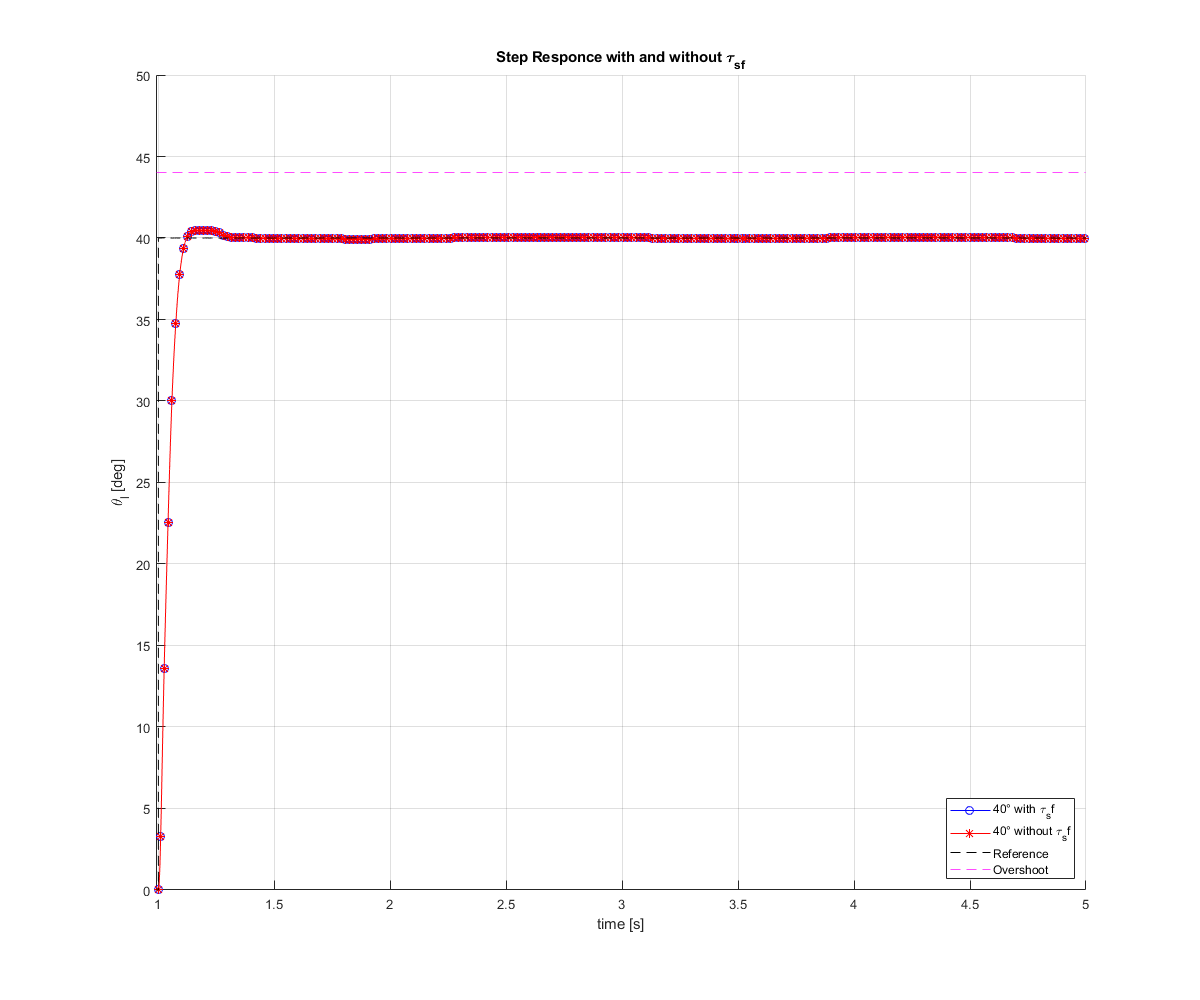

%SIMULATION static friction
figure('Renderer', 'painters', 'Position', [10 10 1200 1000])

hold on;
plot(simdata.robust.step1.p4.t ,simdata.robust.step1.p4.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.robust.step1.p4.t));
plot(simdata.robust.step1.nsf.p4.t,simdata.robust.step1.nsf.p4.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.robust.step1.nsf.p4.t));
plot(simdata.robust.step1.p4.t ,simdata.robust.step1.p4.thl_ref,'k--','MarkerIndices',1:100:length(simdata.robust.step1.p4.t));
yline(40*1.1,'m--')
hold off;
title('Step Responce with and without \tau_{sf}')
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
legend('40° with \tau_sf', '40° without \tau_sf','Reference','Overshoot','Location','southeast');
xlim([0.99 5])
ylim([0 50])
grid on

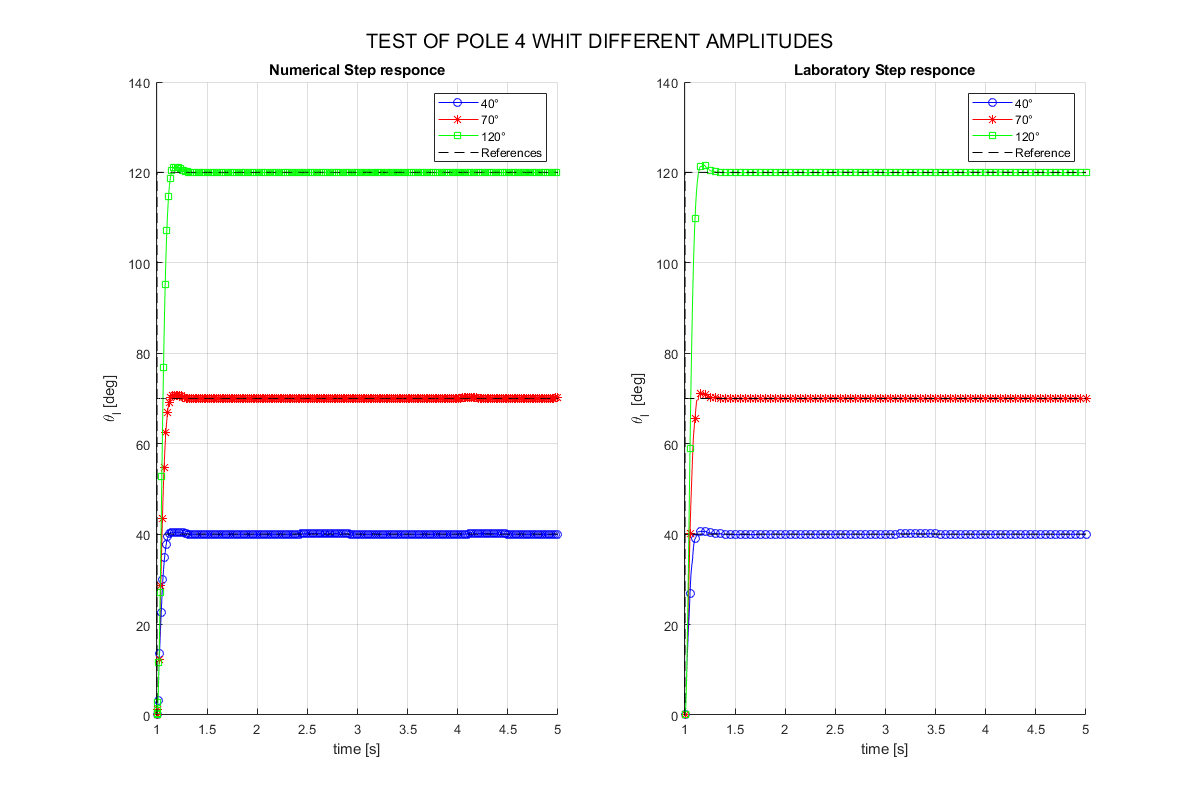

figure('Renderer', 'painters', 'Position', [10 10 1200 800])

subplot(1,2,1);

hold on;
plot(simdata.robust.step1.p4.t,simdata.robust.step1.p4.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.robust.step1.p4.t));
plot(simdata.robust.step2.p4.t,simdata.robust.step2.p4.thl_meas,'r-*','MarkerIndices',1:100:length(simdata.robust.step2.p4.t));
plot(simdata.robust.step3.p4.t,simdata.robust.step3.p4.thl_meas,'g-s','MarkerIndices',1:100:length(simdata.robust.step3.p4.t));

plot(simdata.robust.step1.p4.t,simdata.robust.step1.p4.thl_ref,'k--');
plot(simdata.robust.step2.p4.t,simdata.robust.step2.p4.thl_ref,'k--');
plot(simdata.robust.step3.p4.t,simdata.robust.step3.p4.thl_ref,'k--');

hold off;
legend('40°','70°','120°','References');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
title('Numerical Step responce')
xlim([0.99,5]);
ylim([0 140])

% subplot(2,2,3);
% 
% hold on;
% plot(simdata.robust.step1.t,simdata.robust.step1.u_nosat,'k');
% plot(simdata.robust.step1.p4.t,simdata.robust.step1.p4.u_sat,'b');
% plot(simdata.robust.step2.p4.t,simdata.robust.step2.p4.u_nosat,'k');
% plot(simdata.robust.step2.p4.t,simdata.robust.step2.p4.u_sat,'r');
% plot(simdata.robust.step3.p4.t,simdata.robust.step3.p4.u_nosat,'k');
% plot(simdata.robust.step3.p4.t,simdata.robust.step3.p4.u_sat,'g');
% 
% hold off;
% legend('40°','70°','120°');
% xlabel('time [s]');
% ylabel('u [V]');
% grid on
% xlim([0.9,1.5]);
% ylim([-15,15]);
% title('Numerical Control Signal')
simdata.robust.step1.p4.stepinfo = stepinfo(simdata.robust.step1.p4.thl_meas,simdata.robust.step1.p4.t,'SettlingTimeThreshold',0.05);
simdata.robust.step2.p4.stepinfo = stepinfo(simdata.robust.step2.p4.thl_meas,simdata.robust.step2.p4.t,'SettlingTimeThreshold',0.05);
simdata.robust.step3.p4.stepinfo = stepinfo(simdata.robust.step3.p4.thl_meas,simdata.robust.step3.p4.t,'SettlingTimeThreshold',0.05);

%Practise

subplot(1,2,2);

hold on;
plot(data.robust.AWU.step1.t,data.robust.AWU.step1.thl_meas,'b-o','MarkerIndices',1:50:length(data.robust.AWU.step1.t));
plot(data.robust.AWU.step2.t,data.robust.AWU.step2.thl_meas,'r-*','MarkerIndices',1:50:length(data.robust.AWU.step2.t));
plot(data.robust.AWU.step3.t,data.robust.AWU.step3.thl_meas,'g-s','MarkerIndices',1:50:length(data.robust.AWU.step3.t));
plot(data.robust.AWU.step1.t,data.robust.AWU.step1.thl_ref,'k--');
plot(data.robust.AWU.step2.t,data.robust.AWU.step2.thl_ref,'k--');
plot(data.robust.AWU.step3.t,data.robust.AWU.step3.thl_ref,'k--');
hold off;
legend('40°','70°','120°','Reference');
xlabel('time [s]');
ylabel('\theta_{l}  [deg]');
grid on
xlim([0.99,5]);
title('Laboratory Step responce')
 ylim([0 140])

% subplot(2,2,4);
% 
% hold on;
% %plot(data.robust.step1.t,data.robust.step1.u_nosat,'k');
% plot(data.robust.step1.t,data.robust.step1.u_sat,'b');
% %plot(data.robust.step2.t,data.robust.step2.u_nosat,'k');
% plot(data.robust.step2.t,data.robust.step2.u_sat,'r');
% %plot(data.robust.step3.t,data.robust.step3.u_nosat,'k');
% plot(data.robust.step3.t,data.robust.step3.u_sat,'g');
% 
% hold off;
% legend('40°','70°','120°');
% xlabel('time [s]');
% ylabel('u [V]');
% grid on
% xlim([0.9,1.5]);
% ylim([-15,15]);
% title('Real Control Signal')

sgtitle('TEST OF POLE 4 WHIT DIFFERENT AMPLITUDES')

data.robust.step1.stepinfo = stepinfo(data.robust.step1.thl_meas,data.robust.step1.t,'SettlingTimeThreshold',0.05);
data.robust.step2.stepinfo = stepinfo(data.robust.step2.thl_meas,data.robust.step2.t,'SettlingTimeThreshold',0.05);
data.robust.step3.stepinfo = stepinfo(data.robust.step3.thl_meas,data.robust.step3.t,'SettlingTimeThreshold',0.05);

### 2.2.4 bis ANTI WIND UP (TO DO:test different gains)

ctrl.Kw = 1;%5/ctrl.ts5
step_size = 70;

%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.AWU1.step2.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.AWU1.step2.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.AWU1.step2.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.AWU1.step2.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.AWU.step2.p4.u        = MotorData.signals(3).values;          % control input [V]
%simdata.robust.AWU.step2.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
%simdata.robust.AWU.step2.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


ctrl.Kw = 5/ctrl.ts5;
step_size = 70;
%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.AWU2.step2.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.AWU2.step2.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.AWU2.step2.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.AWU2.step2.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.AWU2.step2.p4.u        = MotorData.signals(3).values;          % control input [V]
simdata.robust.AWU2.step2.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
simdata.robust.AWU2.step2.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


ctrl.Kw = 50;
step_size = 70;
%sim('REALTIME_PART2_robust');
sim('robust_tracking_integral');
simdata.robust.AWU3.step2.p4.t        = MotorData.time;                       % reference angle input [deg]
simdata.robust.AWU3.step2.p4.thl_ref  = MotorData.signals(1).values(:,1);     % angle reference [deg]  
simdata.robust.AWU3.step2.p4.thl_meas = MotorData.signals(1).values(:,2);     % angle measured [deg]      
simdata.robust.AWU3.step2.p4.wl_meas  = MotorData.signals(2).values;          % speed measured [rpm]
%simdata.robust.AWU2.step2.p4.u        = MotorData.signals(3).values;          % control input [V]
%simdata.robust.AWU2.step2.p4.u_nosat  = ControllerData.signals(1).values;     % PID no sat
%simdata.robust.AWU2.step2.p4.u_sat    = ControllerData.signals(2).values;     % PID  sat


figure('Renderer', 'painters', 'Position', [10 10 1300 400])

subplot(1,2,1)
hold on;
plot(simdata.robust.AWU1.step2.p4.t,simdata.robust.AWU1.step2.p4.thl_meas,'b');
plot(simdata.robust.AWU2.step2.p4.t,simdata.robust.AWU2.step2.p4.thl_meas,'r');
plot(simdata.robust.AWU3.step2.p4.t,simdata.robust.AWU3.step2.p4.thl_meas,'g');
plot(simdata.robust.step2.p4.t,simdata.robust.step2.p4.thl_ref,'k--');
hold off;
legend('40°','70°','120°','Without Awu','References');

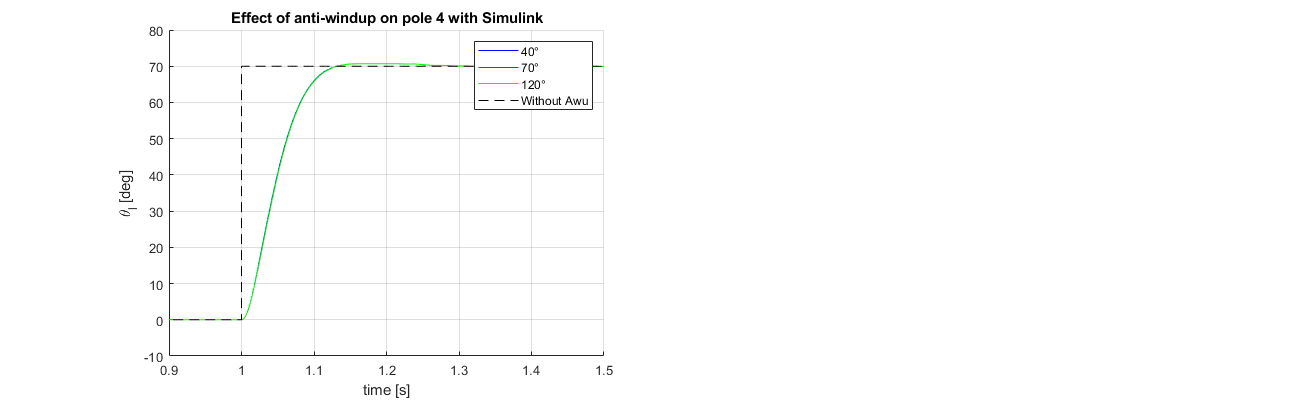

xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
xlim([0.9,1.5]);
title('Effect of anti-windup on pole 4 with Simulink' )


simdata.robust.AWU1.step2.p4.stepinfo = stepinfo(simdata.robust.AWU1.step2.p4.thl_meas,simdata.robust.AWU1.step2.p4.t,'SettlingTimeThreshold',0.05);
simdata.robust.AWU2.step2.p4.stepinfo = stepinfo(simdata.robust.AWU2.step2.p4.thl_meas,simdata.robust.AWU2.step2.p4.t,'SettlingTimeThreshold',0.05);
simdata.robust.AWU3.step2.p4.stepinfo = stepinfo(simdata.robust.AWU3.step2.p4.thl_meas,simdata.robust.AWU3.step2.p4.t,'SettlingTimeThreshold',0.05);

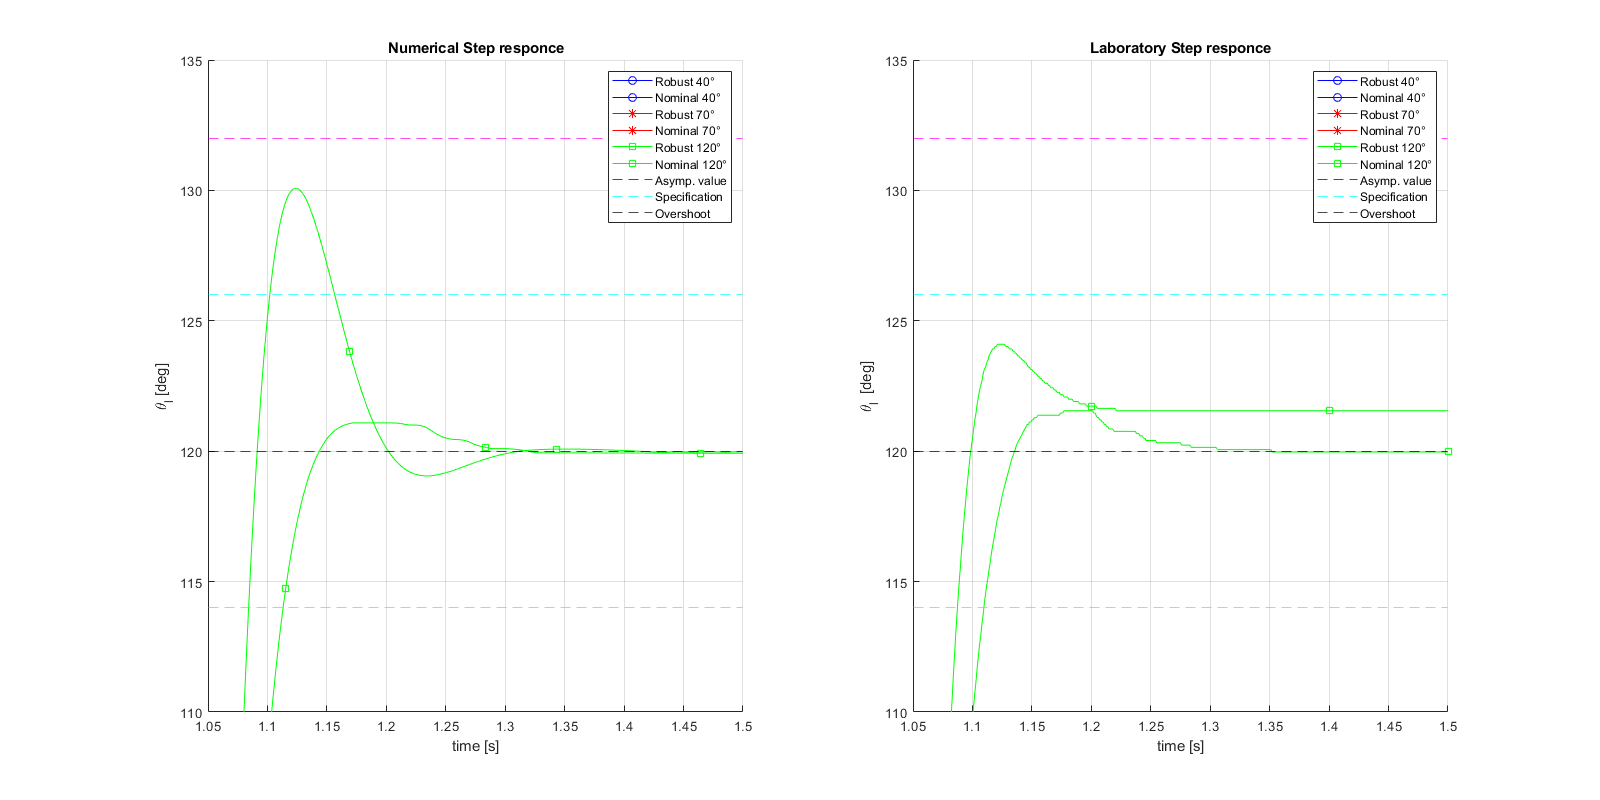

%comparison of nominal and robust tracking
figure('Renderer', 'painters', 'Position', [10 10 1600 800])

subplot(1,2,1);

hold on;
plot(simdata.robust.step1.p4.t,simdata.robust.step1.p4.thl_meas,'b-o','MarkerIndices',1:1000:length(simdata.robust.step1.p4.t));
plot(simdata.nominal.step1.t,simdata.nominal.step1.thl_meas,'b-o','MarkerIndices',1:1000:length(simdata.nominal.step1.t));
plot(simdata.robust.step2.p4.t,simdata.robust.step2.p4.thl_meas,'r-*','MarkerIndices',1:1000:length(simdata.robust.step2.p4.t));
plot(simdata.nominal.step2.t,simdata.nominal.step2.thl_meas,'r-*','MarkerIndices',1:1000:length(simdata.nominal.step2.t));
plot(simdata.robust.step3.p4.t,simdata.robust.step3.p4.thl_meas,'g-s','MarkerIndices',1:1000:length(simdata.robust.step3.p4.t));
plot(simdata.nominal.step3.t,simdata.nominal.step3.thl_meas,'g-s','MarkerIndices',1:1000:length(simdata.nominal.step3.t));
yline(40,'k--')
yline(40*1.05,'c--')
yline(70,'k--')
yline(120,'k--')
yline(40*0.95,'c--')
yline(70*1.05,'c--')
yline(70*0.95,'c--')
yline(120*1.05,'c--')
yline(120*0.95,'c--')
yline(40*1.1,'m--')
yline(70*1.1,'m--')
yline(120*1.1,'m--')
hold off;
legend('Robust 40°','Nominal 40°','Robust 70°','Nominal 70°','Robust 120°','Nominal 120°','Asymp. value','Specification','Overshoot');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
title('Numerical Step responce')
xlim([1.05,1.5]);
ylim([110 135])

simdata.robust.step1.p4.stepinfo = stepinfo(simdata.robust.step1.p4.thl_meas,simdata.robust.step1.p4.t,'SettlingTimeThreshold',0.05);
simdata.robust.step2.p4.stepinfo = stepinfo(simdata.robust.step2.p4.thl_meas,simdata.robust.step2.p4.t,'SettlingTimeThreshold',0.05);
simdata.robust.step3.p4.stepinfo = stepinfo(simdata.robust.step3.p4.thl_meas,simdata.robust.step3.p4.t,'SettlingTimeThreshold',0.05);

%Practise

subplot(1,2,2);

hold on;
plot(data.robust.AWU.step1.t,data.robust.AWU.step1.thl_meas,'b-o','MarkerIndices',1:500:length(data.robust.AWU.step1.t));
plot(data.nominal.step1.t,data.nominal.step1.thl_meas,'b-o','MarkerIndices',1:200:length(data.nominal.step1.t));
plot(data.robust.AWU.step2.t,data.robust.AWU.step2.thl_meas,'r-*','MarkerIndices',1:500:length(data.robust.AWU.step2.t));
plot(data.nominal.step2.t,data.nominal.step2.thl_meas,'r-*','MarkerIndices',1:200:length(data.nominal.step2.t));
plot(data.robust.AWU.step3.t,data.robust.AWU.step3.thl_meas,'g-s','MarkerIndices',1:500:length(data.robust.AWU.step3.t));
plot(data.nominal.step3.t,data.nominal.step3.thl_meas,'g-s','MarkerIndices',1:200:length(data.nominal.step3.t));
title('Step Responce')
yline(40,'k--')
yline(40*1.05,'c--')
yline(70,'k--')
yline(120,'k--')
yline(40*0.95,'c--')
yline(70*1.05,'c--')
yline(70*0.95,'c--')
yline(120*1.05,'c--')
yline(120*0.95,'c--')
yline(40*1.1,'m--')
yline(70*1.1,'m--')
yline(120*1.1,'m--')
hold off;
legend('Robust 40°','Nominal 40°','Robust 70°','Nominal 70°','Robust 120°','Nominal 120°','Asymp. value','Specification','Overshoot');
xlabel('time [s]');
ylabel('\theta_{l}  [deg]');
grid on
xlim([1.05,1.5]);
title('Laboratory Step responce')
ylim([110 135])

### **2.2.5 Robust tracking via error-space approach**

% open simulink model
open_system('robust_tracking_error_space.slx');
set_param('robust_tracking_error_space','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');


%poles
pa=spec.wn*exp(j*(-pi+pi/4));
pb=spec.wn*exp(j*(-pi-pi/4));
pc=spec.wn*exp(j*(-pi+pi/6));
pd=spec.wn*exp(j*(-pi-pi/6));
pe=-spec.wn;
p=[pa pb pc pd pe];

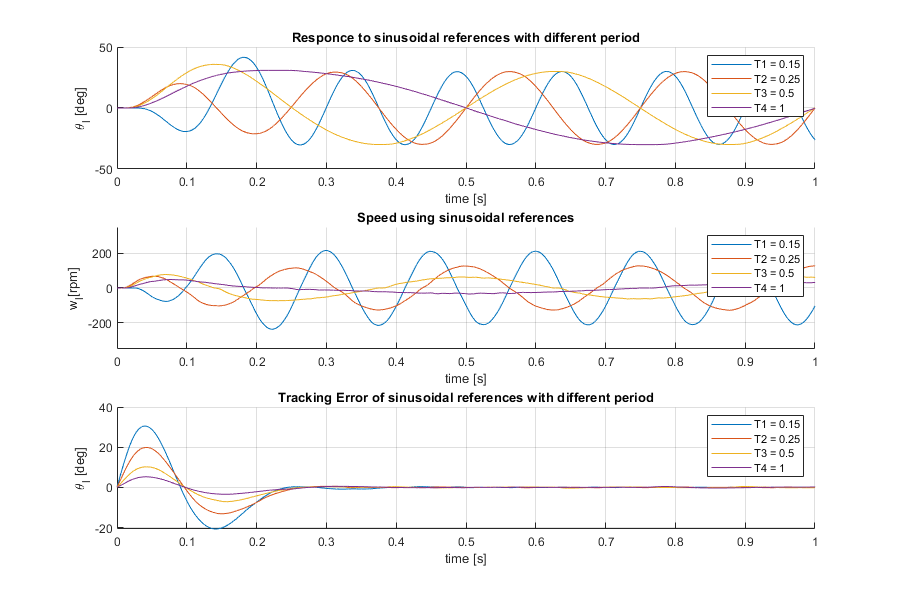

% Design of poles for different period
T = [0.15 0.25 0.5 1];
figure('Renderer', 'painters', 'Position', [10 10 900 600])

for i = 1:4;
    Tr=T(i);
    w0= 2*pi/Tr;
    %compute Az, Bz of the extended model in error-space
    Ar=[0,1,0;0,0,1;0,-w0^2, 0];
    zer=zeros(2,3);
    colonna = [0,0;0,0; C];
    Az= [Ar colonna;zer A];
    Bz=[0;0;0;B];
    Kz=acker(Az,Bz,p);
    
    Ar=30;
    sim('robust_tracking_error_space');
    simdata.errorspace.amp1.Ttest.t    = MotorData.time;
    simdata.errorspace.amp1.thl_ref    = MotorData.signals(1).values(:,1);
    simdata.errorspace.amp1.thl_meas   = squeeze(MotorData.signals(1).values(:,2)); %MotorData.signals(1).values(:,2);
    simdata.errorspace.amp1.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
    simdata.errorspace.amp1.e          = squeeze(MotorData.signals(3).values);
    simdata.errorspace.amp1.u          = squeeze(MotorData.signals(4).values);
     
    subplot(3,1,1);
    hold on;
    grid on;
    plot(simdata.errorspace.amp1.Ttest.t,simdata.errorspace.amp1.thl_meas);
    legend('T1 = 0.15','T2 = 0.25','T3 = 0.5','T4 = 1','Reference');
    xlabel('time [s]');
    ylabel('\theta_{l} [deg]');
    title('Responce to sinusoidal references with different period')
    xlim([0 1]);
    ylim([-50 50])
    hold off
    
    subplot(3,1,2);
    hold on;
    plot(simdata.errorspace.amp1.Ttest.t,simdata.errorspace.amp1.wl_meas);
    legend('T1 = 0.15','T2 = 0.25','T3 = 0.5','T4 = 1');
    xlabel('time [s]');
    ylabel('w_{l}[rpm]');
    title('Speed using sinusoidal references')
    hold off
    xlim([0 1]);
    ylim([-350 350])
    grid on
    
    subplot(3,1,3);
    hold on;
    grid on;
    plot(simdata.errorspace.amp1.Ttest.t,simdata.errorspace.amp1.e);
    legend('T1 = 0.15','T2 = 0.25','T3 = 0.5','T4 = 1');
    xlabel('time [s]');
    ylabel('\theta_{l} [deg]');
    title('Tracking Error of sinusoidal references with different period')
    xlim([0 1]);
    hold off
    
end

### 2.2.6 

%Amplitude 30°
Tr = T(3);
w0= 2*pi/Tr;
%compute Az, Bz of the extended model in error-space
Ar=[0,1,0;0,0,1;0,-w0^2, 0];
zer=zeros(2,3);
colonna = [0,0;0,0; C];
Az= [Ar colonna;zer A];
Bz=[0;0;0;B];
Kz=acker(Az,Bz,p);

    
Ar=30;
sim('robust_tracking_error_space');

simdata.errorspace.amp1.t          = MotorData.time;
simdata.errorspace.amp1.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp1.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp1.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp1.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp1.u          = squeeze(MotorData.signals(4).values);



%Amplitude 60°
Ar=60;
sim('robust_tracking_error_space');

simdata.errorspace.amp2.t          = MotorData.time;
simdata.errorspace.amp2.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp2.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp2.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp2.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp2.u          = squeeze(MotorData.signals(4).values);

%Amplitude 90°
Ar=90;
sim('robust_tracking_error_space');

simdata.errorspace.amp3.t          = MotorData.time;
simdata.errorspace.amp3.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp3.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp3.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp3.e          = squeeze(MotorData.signals(3).values());
simdata.errorspace.amp3.u          = squeeze(MotorData.signals(4).values);

%ideal sim
%Amplitude 30°
Tr = T(3);
Ar=30;
sim('robust_tracking_error_space');

simdata.errorspace.amp1.nsf.t          = MotorData.time;
simdata.errorspace.amp1.nsf.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp1.nsf.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp1.nsf.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp1.nsf.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp1.nsf.u          = squeeze(MotorData.signals(4).values);


%Amplitude 60°
Ar=60;
sim('robust_tracking_error_space');

simdata.errorspace.amp2.nsf.t          = MotorData.time;
simdata.errorspace.amp2.nsf.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp2.nsf.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp2.nsf.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp2.nsf.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp2.nsf.u          = squeeze(MotorData.signals(4).values);

%Amplitude 90°
Ar=90;
sim('robust_tracking_error_space');

simdata.errorspace.amp3.nsf.t          = MotorData.time;
simdata.errorspace.amp3.nsf.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp3.nsf.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp3.nsf.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp3.nsf.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp3.nsf.u          = squeeze(MotorData.signals(4).values);

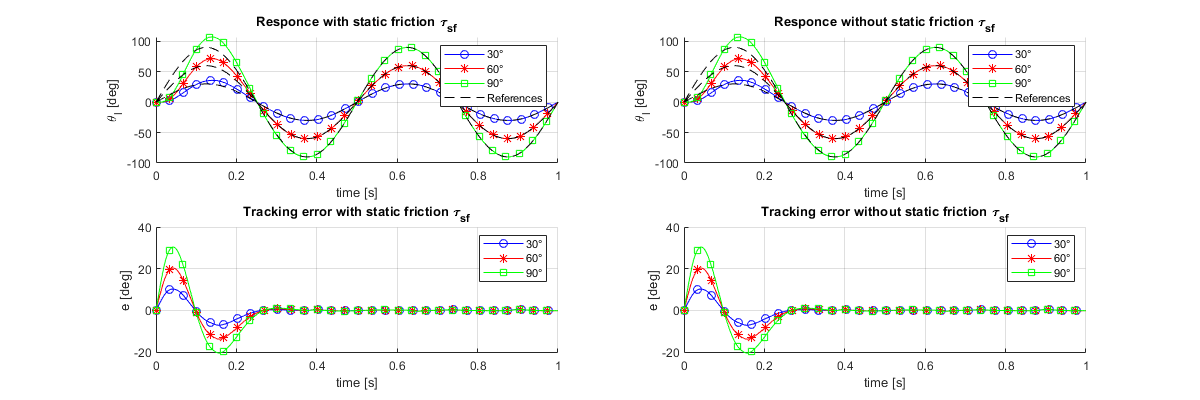

%ideal vs real
figure('Renderer', 'painters', 'Position', [10 10 1200 400])

subplot(2,2,1);
hold on;
grid on;
plot(simdata.errorspace.amp1.t ,simdata.errorspace.amp1.thl_meas,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp2.t ,simdata.errorspace.amp2.thl_meas,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.t));
plot(simdata.errorspace.amp3.t ,simdata.errorspace.amp3.thl_meas,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.t));
plot(simdata.errorspace.amp1.t,simdata.errorspace.amp1.thl_ref,'k--');
plot(simdata.errorspace.amp2.t,simdata.errorspace.amp2.thl_ref,'k--');
plot(simdata.errorspace.amp3.t,simdata.errorspace.amp3.thl_ref,'k--');
hold off;
legend('30°','60°','90°','References');
xlabel('time [s]');
ylabel(['\theta_{l} [deg]']);
grid on
title('Responce with static friction \tau_{sf}')
xlim([0 1])

subplot(2,2,3);
hold on;
grid on;
plot(simdata.errorspace.amp1.t ,simdata.errorspace.amp1.e,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp2.t ,simdata.errorspace.amp2.e,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.t));
plot(simdata.errorspace.amp3.t ,simdata.errorspace.amp3.e,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.t));

hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel(['e [deg]']);
grid on
title('Tracking error with static friction \tau_{sf}')
xlim([0 1])

subplot(2,2,2);
hold on;
grid on;
plot(simdata.errorspace.amp1.nsf.t ,simdata.errorspace.amp1.nsf.thl_meas,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.nsf.t));
plot(simdata.errorspace.amp2.nsf.t ,simdata.errorspace.amp2.nsf.thl_meas,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.nsf.t));
plot(simdata.errorspace.amp3.nsf.t ,simdata.errorspace.amp3.nsf.thl_meas,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.nsf.t));
plot(simdata.errorspace.amp1.nsf.t,simdata.errorspace.amp1.nsf.thl_ref,'k--');
plot(simdata.errorspace.amp2.nsf.t,simdata.errorspace.amp2.nsf.thl_ref,'k--');
plot(simdata.errorspace.amp3.nsf.t,simdata.errorspace.amp3.nsf.thl_ref,'k--');
hold off;
legend('30°','60°','90°','References');
xlabel('time [s]');
ylabel(['\theta_{l} [deg]']);
grid on
title('Responce without static friction \tau_{sf}')
xlim([0 1])

subplot(2,2,4);
hold on;
grid on;
plot(simdata.errorspace.amp1.nsf.t ,simdata.errorspace.amp1.nsf.e,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.nsf.t));
plot(simdata.errorspace.amp2.nsf.t ,simdata.errorspace.amp2.nsf.e,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.nsf.t));
plot(simdata.errorspace.amp3.nsf.t ,simdata.errorspace.amp3.nsf.e,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.nsf.t));
hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel(['e [deg]']);
grid on
title('Tracking error without static friction \tau_{sf}')
xlim([0 1])

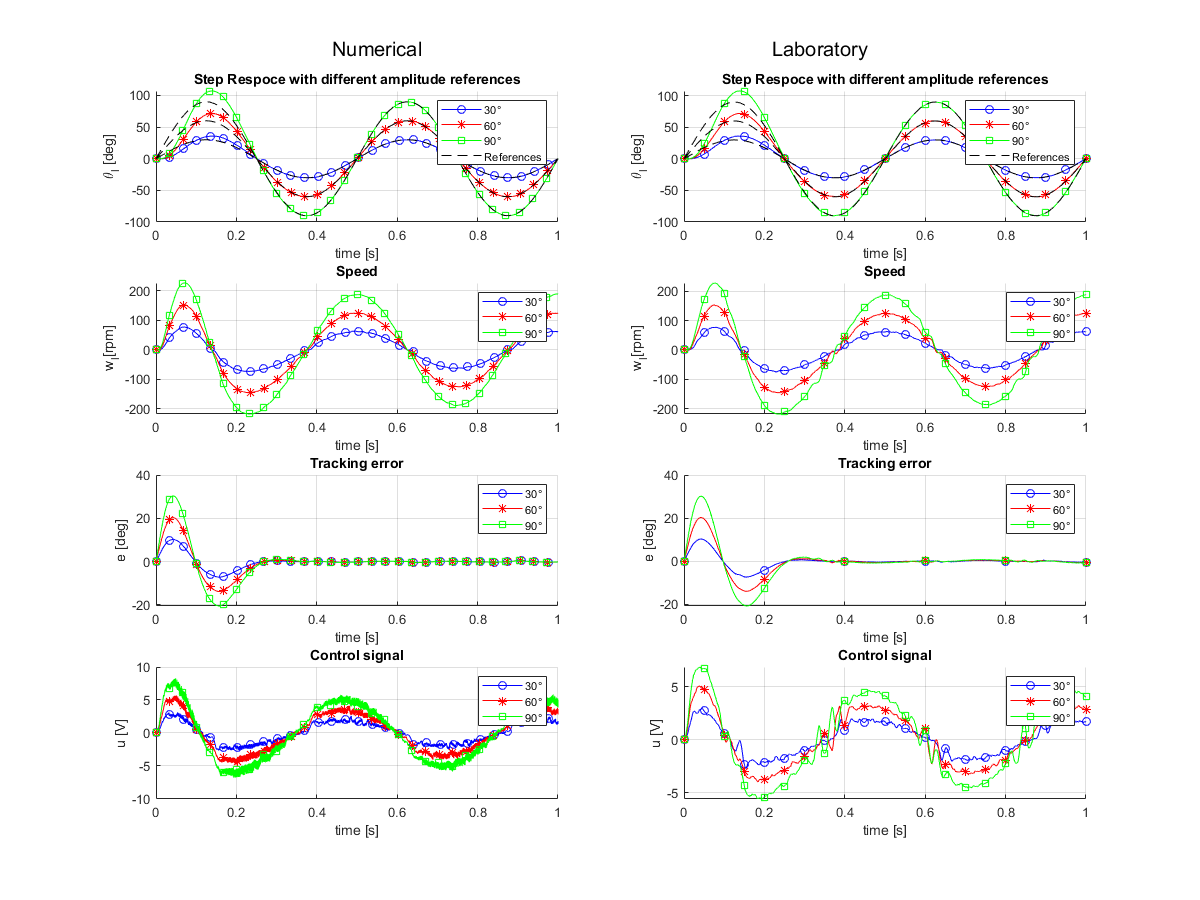

%plot of the responses at 30°, 60°, 90°
figure('Renderer', 'painters', 'Position', [10 10 1200 900])

subplot(4,2,1);
hold on;
grid on;
plot(simdata.errorspace.amp1.t ,simdata.errorspace.amp1.thl_meas,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp2.t ,simdata.errorspace.amp2.thl_meas,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.t));
plot(simdata.errorspace.amp3.t ,simdata.errorspace.amp3.thl_meas,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.t));
plot(simdata.errorspace.amp1.t,simdata.errorspace.amp1.thl_ref,'k--');
plot(simdata.errorspace.amp2.t,simdata.errorspace.amp2.thl_ref,'k--');
plot(simdata.errorspace.amp3.t,simdata.errorspace.amp3.thl_ref,'k--');
hold off;
legend('30°','60°','90°','References');
xlabel('time [s]');
ylabel(['\theta_{l} [deg]']);
grid on
title('Step Respoce with different amplitude references')
xlim([0 1])

subplot(4,2,3);
hold on;
plot(simdata.errorspace.amp1.t,simdata.errorspace.amp1.wl_meas,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp2.t,simdata.errorspace.amp2.wl_meas,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.t));
plot(simdata.errorspace.amp3.t,simdata.errorspace.amp3.wl_meas,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.t));
hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel('w_{l}[rpm]');
grid on
title('Speed')
xlim([0 1])

subplot(4,2,5);
hold on;
grid on;
plot(simdata.errorspace.amp1.t ,simdata.errorspace.amp1.e,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp2.t ,simdata.errorspace.amp2.e,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.t));
plot(simdata.errorspace.amp3.t ,simdata.errorspace.amp3.e,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.t));
hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel(['e [deg]']);
grid on
title('Tracking error')
xlim([0 1])

subplot(4,2,7);
hold on;
plot(simdata.errorspace.amp1.t,simdata.errorspace.amp1.u,'b-o','MarkerIndices',1:200:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp2.t,simdata.errorspace.amp2.u,'r-*','MarkerIndices',1:200:length(simdata.errorspace.amp2.t));
plot(simdata.errorspace.amp3.t,simdata.errorspace.amp3.u,'g-s','MarkerIndices',1:200:length(simdata.errorspace.amp3.t));
hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel('u [V]');
grid on
title('Control signal')
xlim([0 1])

%Practice
subplot(4,2,2);
hold on;
grid on;
plot(data.errorspace.amp1.t,data.errorspace.amp1.thl_meas,'b-o','MarkerIndices',1:50:length(data.errorspace.amp1.t));
plot(data.errorspace.amp2.t,data.errorspace.amp2.thl_meas,'r-*','MarkerIndices',1:50:length(data.errorspace.amp2.t));
plot(data.errorspace.amp3.t,data.errorspace.amp3.thl_meas,'g-s','MarkerIndices',1:50:length(data.errorspace.amp3.t));
plot(data.errorspace.amp1.t,data.errorspace.amp1.thl_ref,'k--');
plot(data.errorspace.amp2.t,data.errorspace.amp2.thl_ref,'k--');
plot(data.errorspace.amp3.t,data.errorspace.amp3.thl_ref,'k--');
hold off;
legend('30°','60°','90°','References');
xlabel('time [s]');
ylabel(['\theta_{l} [deg]']);
grid on
title('Step Respoce with different amplitude references')
xlim([0 1])

subplot(4,2,4);
hold on;
plot(data.errorspace.amp1.t,data.errorspace.amp1.wl_meas,'b-o','MarkerIndices',1:50:length(data.errorspace.amp1.t));
plot(data.errorspace.amp2.t,data.errorspace.amp2.wl_meas,'r-*','MarkerIndices',1:50:length(data.errorspace.amp2.t));
plot(data.errorspace.amp3.t,data.errorspace.amp3.wl_meas,'g-s','MarkerIndices',1:50:length(data.errorspace.amp3.t));
hold off;
grid on
legend('30°','60°','90°');
xlabel('time [s]');
ylabel('w_{l}[rpm]');
title('Speed')
xlim([0 1])

%Practice
subplot(4,2,6);
hold on;
grid on;
plot(data.errorspace.amp1.t ,data.errorspace.amp1.e,'b-o','MarkerIndices',1:200:length(data.errorspace.amp1.t));
plot(data.errorspace.amp2.t ,data.errorspace.amp2.e,'r-*','MarkerIndices',1:200:length(data.errorspace.amp2.t));
plot(data.errorspace.amp3.t ,data.errorspace.amp3.e,'g-s','MarkerIndices',1:200:length(data.errorspace.amp3.t));
hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel(['e [deg]']);
grid on
title('Tracking error')
xlim([0 1])

subplot(4,2,8);
hold on;
plot(data.errorspace.amp1.t,data.errorspace.amp1.u,'b-o','MarkerIndices',1:50:length(data.errorspace.amp1.t));
plot(data.errorspace.amp2.t,data.errorspace.amp2.u,'r-*','MarkerIndices',1:50:length(data.errorspace.amp2.t));
plot(data.errorspace.amp3.t,data.errorspace.amp3.u,'g-s','MarkerIndices',1:50:length(data.errorspace.amp3.t));
hold off;
legend('30°','60°','90°');
xlabel('time [s]');
ylabel('u [V]');
title('Control signal')
xlim([0 1])

sgtitle('Numerical                                                               Laboratory')
grid on

### 2.2.7

%Amplitude of 40°, period Tr=0.1s and control used before
Ar=40;
Tr=0.1;
sim('robust_tracking_error_space');


%tracking error
simdata.errorspace.amp1.Tr.t          = MotorData.time;
simdata.errorspace.amp1.Tr.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp1.Tr.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp1.Tr.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp1.Tr.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp1.Tr.u          = squeeze(MotorData.signals(4).values);

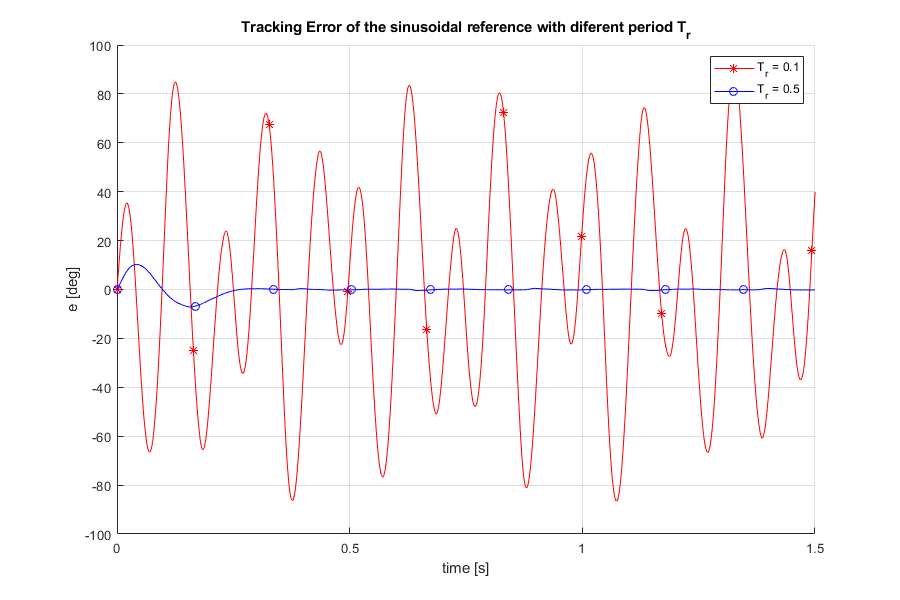

%compare the two tracking errors 
figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
grid on;
plot(simdata.errorspace.amp1.Tr.t,simdata.errorspace.amp1.Tr.e ,'r-*','MarkerIndices',1:1000:length(simdata.errorspace.amp1.Tr.t));
plot(simdata.errorspace.amp1.t ,simdata.errorspace.amp1.e,'b-o','MarkerIndices',1:1000:length(simdata.errorspace.amp1.t));
hold off;
legend('T_{r} = 0.1','T_{r} = 0.5');
xlabel('time [s]');
ylabel('e [deg]');
grid on
title('Tracking Error of the sinusoidal reference with diferent period T_r')
xlim([0 1.5])

### 2.2.8

%simulation with step_size = 40
step_size = 40;
sim('robust_tracking_error_space');

simdata.errorspace.amp1.step.t          = MotorData.time;
simdata.errorspace.amp1.step.thl_ref    = MotorData.signals(1).values(:,1);
simdata.errorspace.amp1.step.thl_meas   = squeeze(MotorData.signals(1).values(:,2));%MotorData.signals(1).values(:,2);
simdata.errorspace.amp1.step.wl_meas    = squeeze(MotorData.signals(2).values);%MotorData.signals(2).values;
simdata.errorspace.amp1.step.e          = squeeze(MotorData.signals(3).values);
simdata.errorspace.amp1.step.u          = squeeze(MotorData.signals(4).values);

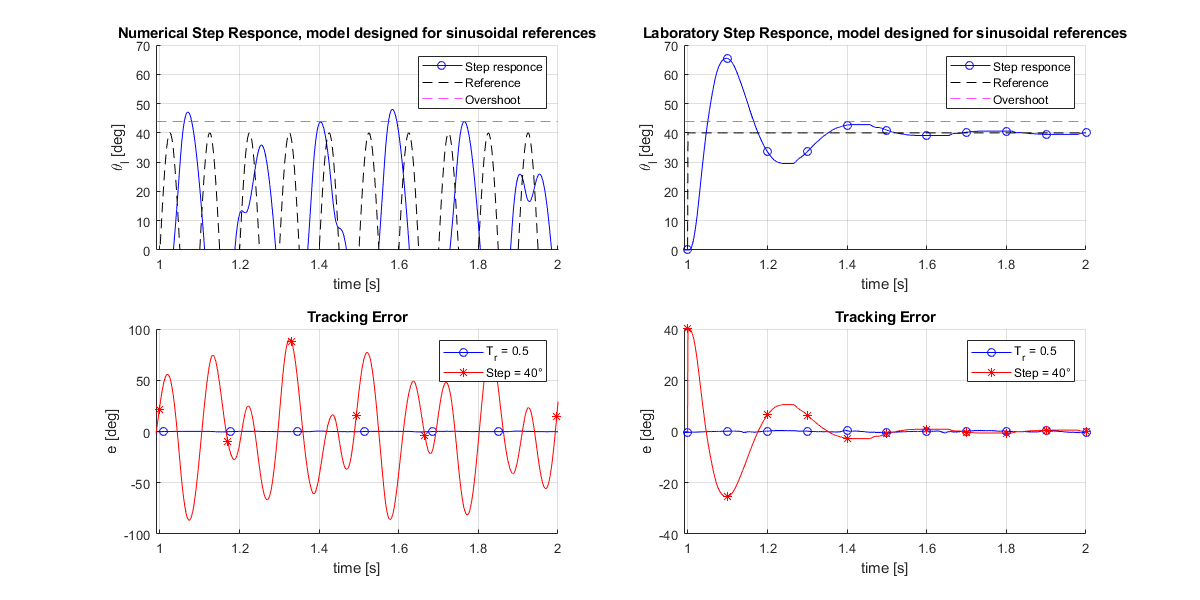

%plot of the step response
figure('Renderer', 'painters', 'Position', [10 10 1200 600])

subplot(2,2,1)
hold on;
grid on;
plot(simdata.errorspace.amp1.step.t,simdata.errorspace.amp1.step.thl_meas,'b-o','MarkerIndices',1:1000:length(simdata.errorspace.amp1.step.t));
plot(simdata.errorspace.amp1.step.t,simdata.errorspace.amp1.step.thl_ref,'k--','MarkerIndices',1:1000:length(simdata.errorspace.amp1.step.t));
yline(step_size*1.1,'m--')
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
title('Numerical Step Responce, model designed for sinusoidal references')
legend('Step responce', 'Reference','Overshoot')
xlim([0.99 2])
ylim([0 70])
grid on;

subplot(2,2,3)
hold on;
grid on;
plot(simdata.errorspace.amp1.t ,simdata.errorspace.amp1.e,'b-o','MarkerIndices',1:1000:length(simdata.errorspace.amp1.t));
plot(simdata.errorspace.amp1.step.t,simdata.errorspace.amp1.step.e ,'r-*','MarkerIndices',1:1000:length(simdata.errorspace.amp1.step.t));
xlabel('time [s]');
ylabel('e [deg]');
title('Tracking Error')
legend('T_{r} = 0.5','Step = 40°');
xlim([0.99 2])

grid on;

subplot(2,2,2)
hold on;
grid on;
plot(data.errorspace.step.t,data.errorspace.step.thl_meas,'b-o','MarkerIndices',1:100:length(data.errorspace.step.t));
plot(data.errorspace.step.t,data.errorspace.step.thl_ref,'k--','MarkerIndices',1:100:length(data.errorspace.step.t));
yline(step_size*1.1,'m--')
hold off;
legend('Step responce', 'Reference','Overshoot');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
xlim([0.99 2])
ylim([0 70])
title('Laboratory Step Responce, model designed for sinusoidal references')

subplot(2,2,4)
hold on;
grid on;
plot(data.errorspace.amp1.t ,data.errorspace.amp1.e,'b-o','MarkerIndices',1:100:length(data.errorspace.amp1.t));
plot(data.errorspace.step.t,data.errorspace.step.e ,'r-*','MarkerIndices',1:100:length(data.errorspace.step.t));
hold off;
legend('T_{r} = 0.5','Step = 40°');
xlabel('time [s]');
ylabel('e [deg]');
grid on
xlim([0.99 2])

title('Tracking Error')

%PRACTICE
step_size = 40;

% simdata.errorspace.step.t          = MotorData.time;
% simdata.errorspace.step.thl_ref    = MotorData.signals(1).values(:,1);
% simdata.errorspace.step.thl_meas   = MotorData.signals(1).values(:,2);
% simdata.errorspace.step.wl_meas    = MotorData.signals(2).values;
% simdata.errorspace.step.e          = MotorData.signals(3).values;
% simdata.errorspace.step.u          = squeeze(MotorData.signals(4).values);

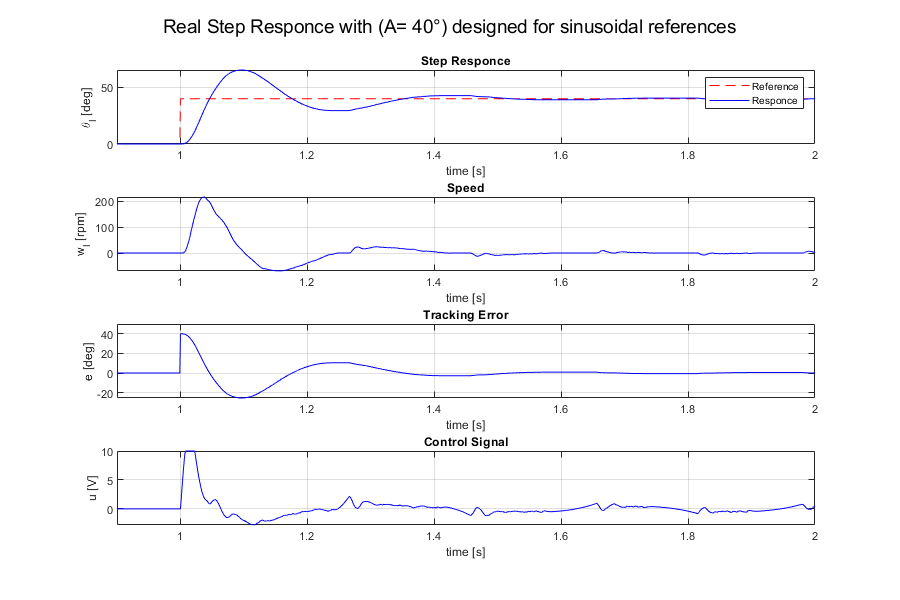

% figure('Renderer', 'painters', 'Position', [10 10 900 600])
% subplot(4,1,1);
% plot(simdata.errorspace.step.t,simdata.errorspace.step.thl_ref,'r',simdata.errorspace.step.t,simdata.errorspace.step.thl_meas,'b');
% legend('ref','meas');
% xlabel('time [s]');
% ylabel('angle [deg]');
% grid on
% 
% subplot(4,1,2);
% plot(simdata.errorspace.step.t,simdata.errorspace.step.wl_meas,'b');
% xlabel('time [s]');
% ylabel('speed [rpm]');
% grid on
% 
% subplot(4,1,3);
% plot(simdata.errorspace.step.t,simdata.errorspace.step.e,'b');
% xlabel('time [s]');
% ylabel('e [deg]');
% grid on
% 
% subplot(4,1,4);
% plot(simdata.errorspace.step.t,simdata.errorspace.step.u,'b');
% xlabel('time [s]');
% ylabel('u [V]');
% grid on

%Practice
figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,1,1);
plot(data.errorspace.step.t,data.errorspace.step.thl_ref,'r--',data.errorspace.step.t,data.errorspace.step.thl_meas,'b');
legend('Reference','Responce');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
title('Step Responce')
xlim([0.9 2])
grid on

subplot(4,1,2);
plot(data.errorspace.step.t,data.errorspace.step.wl_meas,'b');
xlabel('time [s]');
ylabel('w_{l} [rpm]');
title('Speed')
xlim([0.9 2])
grid on

subplot(4,1,3);
plot(data.errorspace.step.t,data.errorspace.step.e,'b');
xlabel('time [s]');
ylabel('e [deg]');
title('Tracking Error')
xlim([0.9 2])
grid on

subplot(4,1,4);
plot(data.errorspace.step.t,data.errorspace.step.u,'b');
xlabel('time [s]');
ylabel('u [V]');
title('Control Signal')
xlim([0.9 2])
grid on
sgtitle('Real Step Responce with (A= 40°) designed for sinusoidal references')

### 2.2.9 Extended state-estimator method

% load variables in workspace of LAB0 (parameters according to motor 8)
load params_inertial_case.mat
load params_estimated_LAB0.mat
load PID_params_LAB0.mat

Beq = Beq_hat;                           % mot.B + mld.B/gbox.N^2;    
Jeq = Jeq_hat;
model.km = (drv.dcgain*mot.Kt)/(Req*Beq + mot.Kt*mot.Ke);
model.Tm = (Req*Jeq)/(Req*Beq + mot.Kt*mot.Ke);
sens.enc.pulse2deg = 360/2000; % in lab da cambiare in 360/4096

% define H1 filter
H1.wc = 2*pi*50;   
H1.d = 1/sqrt(2);
H1s = tf([H1.wc^2,0],[1, 2*H1.d*H1.wc, H1.wc^2]);
[numH1, denH1] = tfdata(H1s,'v');

%specs
spec.ts5    = 0.15;         % Settling-time
spec.Mp     = 0.1;          % Overshoot
spec.damp   = log(1/spec.Mp) / (sqrt(pi^2+(log(1/spec.Mp))^2));
spec.wn   = 3 / (spec.damp*spec.ts5);

% open simulink model
open_system('robust_tracking_extended_estimator.slx');
set_param('robust_tracking_extended_estimator','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

%"controller" eigenvalues and "estimator" eigenvalues
pc1=-20*spec.damp*spec.wn + j*spec.wn*sqrt(1-spec.damp^2);
pc2=-20*spec.damp*spec.wn - j*spec.wn*sqrt(1-spec.damp^2);
pc = [pc1 , pc2];

pe1=2*spec.wn*exp(j*(-pi+pi/3));
pe2 = conj(pe1);
pe3=2*spec.wn*exp(j*(-pi+pi/6));
pe4 = conj(pe3);
pe5=-2*spec.wn;
pe =[pe1 pe2 pe3 pe4 pe5];

% reference
T = [0.15 0.25 0.5 1];
Tr = 0.5;
w0 = 1/Tr;
Ar = 30;

% Define system
Ap = [0 1 0 ; 0 0 1 ; 0 -w0^2 0];
Cp = [1 0 0];
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;
zer = zeros(3,2);
BCp = B*Cp;

Ae = [Ap , zer;
      BCp , A ];
Be = [0 ; 0 ; 0 ; B ];
Ce = [0 , 0 , 0 , C];
K3 = place(A,B,pc);
Le = place(Ae.',Ce.',pe).';

Aest = Ae - Le*Ce;
Best = [ Be Le];
Cest = eye(5);
Dest = zeros(5,2);

#### 9.6: simulation with 30 deg sinusoidal, Tr = 0.5;

Ar = 30;
Tr = 0.5;

sim('robust_tracking_extended_estimator.slx');

simdata.extended.t          = MotorData.time;
simdata.extended.thl_ref    = MotorData.signals(1).values(:,1);
simdata.extended.thl_meas   = squeeze(MotorData.signals(1).values(:,2));
simdata.extended.wl_meas    = squeeze(MotorData.signals(2).values);
simdata.extended.u          = squeeze(MotorData.signals(4).values);
simdata.extended.thl_err    = squeeze(MotorData.signals(3).values);

Ar = 60;
Tr = 0.5;

sim('robust_tracking_extended_estimator.slx');

simdata.extended2.t          = MotorData.time;
simdata.extended2.thl_ref    = MotorData.signals(1).values(:,1);
simdata.extended2.thl_meas   = squeeze(MotorData.signals(1).values(:,2));
simdata.extended2.wl_meas    = squeeze(MotorData.signals(2).values);
simdata.extended2.u          = squeeze(MotorData.signals(4).values);
simdata.extended2.thl_err    = squeeze(MotorData.signals(3).values);

Ar = 90;
Tr = 0.5;

sim('robust_tracking_extended_estimator.slx');

simdata.extended3.t          = MotorData.time;
simdata.extended3.thl_ref    = MotorData.signals(1).values(:,1);
simdata.extended3.thl_meas   = squeeze(MotorData.signals(1).values(:,2));
simdata.extended3.wl_meas    = squeeze(MotorData.signals(2).values);
simdata.extended3.u          = squeeze(MotorData.signals(4).values);
simdata.extended3.thl_err    = squeeze(MotorData.signals(3).values);

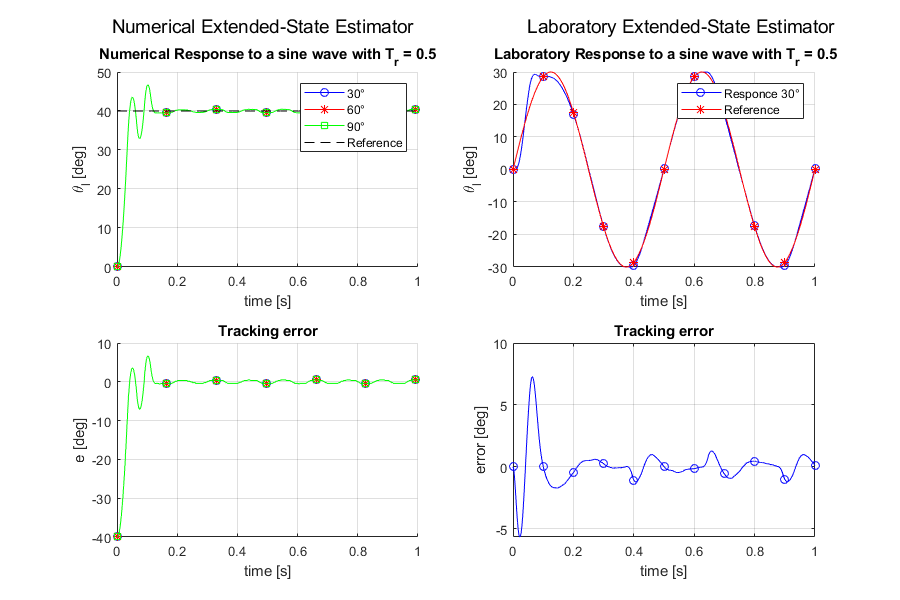

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,2,1);
hold on;
grid on;
plot (simdata.extended.t  , simdata.extended.thl_meas,'b-o','MarkerIndices',1:1000:length(simdata.extended.t));
plot (simdata.extended2.t  , simdata.extended2.thl_meas,'r-*','MarkerIndices',1:1000:length(simdata.extended2.t));
plot (simdata.extended3.t  , simdata.extended3.thl_meas,'g-s','MarkerIndices',1:1000:length(simdata.extended3.t));
plot (simdata.extended.t  , simdata.extended.thl_ref, 'k--','MarkerIndices',1:1000:length(simdata.extended.t));
plot (simdata.extended2.t  , simdata.extended2.thl_ref, 'k--','MarkerIndices',1:1000:length(simdata.extended2.t));
plot (simdata.extended3.t  , simdata.extended3.thl_ref, 'k--','MarkerIndices',1:1000:length(simdata.extended3.t));
hold off;
legend('30°','60°','90°','Reference');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
title('Numerical Response to a sine wave with T_r = 0.5')
xlim([0 1])

subplot(2,2,3);
hold on;
plot(simdata.extended.t,simdata.extended.thl_err,'b-o','MarkerIndices',1:1000:length(simdata.extended.t));
plot(simdata.extended2.t,simdata.extended2.thl_err,'r-*','MarkerIndices',1:1000:length(simdata.extended2.t));
plot(simdata.extended3.t,simdata.extended3.thl_err,'g-s','MarkerIndices',1:1000:length(simdata.extended3.t));
hold off;
xlabel('time [s]');
ylabel('e [deg]');
xlim([0 1])
grid on
title('Tracking error')

%Practice
subplot(2,2,2);
hold on
plot(data.extended.t,data.extended.thl_meas,'b-o','MarkerIndices',1:100:length(data.extended.t));
plot(data.extended.t,data.extended.thl_ref,'r-*','MarkerIndices',1:100:length(data.extended.t));
legend('Responce 30°','Reference');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
title(' Laboratory Response to a sine wave with T_r = 0.5')
grid on
hold off
xlim([0 1])

subplot(2,2,4);
plot(data.extended.t,data.extended.thl_err,'b-o','MarkerIndices',1:100:length(data.extended.t));
xlabel('time [s]');
ylabel('error [deg]');
xlim([0 1])
title('Tracking error')
grid on

% subplot(4,1,4);
% plot(data.extended.t,data.extended.u,'b');
% xlabel('time [s]');
% ylabel('u [V]');
% title('Control Signal')
% grid on
% xlim([0 2])
sgtitle('         Numerical Extended-State Estimator                      Laboratory Extended-State Estimator')

#### 9.7: simulation with 40 deg sinusoidal, Tr = 0.1 but using the design

% build on Tr_original = 0.5 (w0 is defined above);

Ar = 40;
Tr = 0.1;

sim('robust_tracking_extended_estimator.slx');
simdata.extended.step.t          = MotorData.time;
simdata.extended.step.thl_ref    = MotorData.signals(1).values(:,1);
simdata.extended.step.thl_meas   = MotorData.signals(1).values(:,2);
simdata.extended.step.wl_meas    = MotorData.signals(2).values;
simdata.extended.step.u          = squeeze(MotorData.signals(4).values);
simdata.extended.step.thl_err    = squeeze(MotorData.signals(3).values);

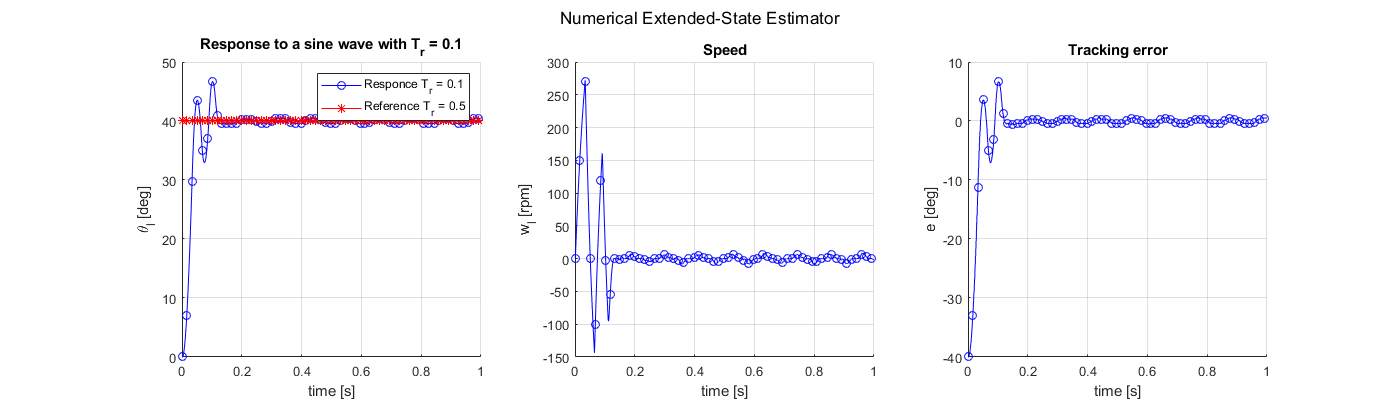

figure('Renderer', 'painters', 'Position', [10 10 1400 400])
subplot(1,3,1);
hold on;
grid on;
plot (simdata.extended.step.t , simdata.extended.step.thl_meas,'b-o','MarkerIndices',1:100:length(simdata.extended.step.t));
plot (simdata.extended.step.t , simdata.extended.step.thl_ref, 'r-*','MarkerIndices',1:100:length(simdata.extended.step.t));
hold off;
legend('Responce T_r = 0.1','Reference T_r = 0.5');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
title('Response to a sine wave with T_r = 0.1')
xlim([0 1])

subplot(1,3,2);
hold on;
plot(simdata.extended.step.t,simdata.extended.step.wl_meas,'b-o','MarkerIndices',1:100:length(simdata.extended.step.t));
hold off;
xlabel('time [s]');
ylabel('w_{l} [rpm]');
title('Speed')
grid on
xlim([0 1])

subplot(1,3,3);
hold on;
plot(simdata.extended.step.t,simdata.extended.step.thl_err ,'b-o','MarkerIndices',1:100:length(simdata.extended.step.t));
hold off;
xlabel('time [s]');
ylabel('e [deg]');
title('Tracking error')
xlim([0 1])

grid on
sgtitle('Numerical Extended-State Estimator')

#### 9.8 reference = step_40 deg;

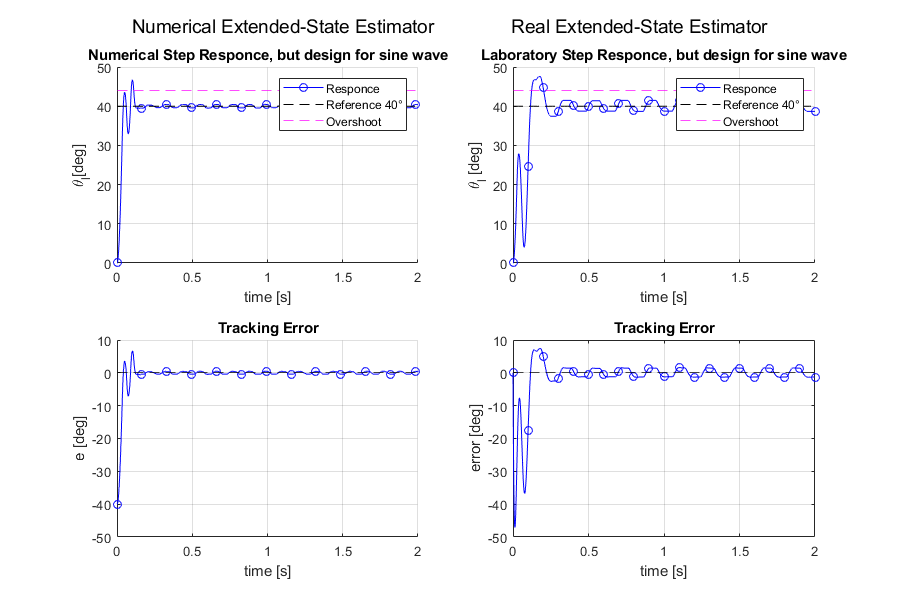

step_size = 40;
sim('robust_tracking_extended_estimator.slx');
%mot.testep2    = MotorData.time;
%mot.thlestep2  = MotorData.signals(1).values;
simdata.extended.step.Tr.terror = MotorData.time;
simdata.extended.step.Tr.thl_ref    = MotorData.signals(1).values(:,1);
simdata.extended.step.Tr.thl_mean    = MotorData.signals(1).values(:,2);
simdata.extended.step.Tr.e =squeeze(MotorData.signals(3).values);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,2,1)
hold on;
grid on;
plot(simdata.extended.step.Tr.terror,simdata.extended.step.Tr.thl_mean,'b-o','MarkerIndices',1:1000:length(simdata.extended.step.Tr.terror));
plot(simdata.extended.step.Tr.terror,simdata.extended.step.Tr.thl_ref,'k--','MarkerIndices',1:1000:length(simdata.extended.step.Tr.terror));
yline(44,'m--')
legend('Responce','Reference 40°','Overshoot');
xlabel('time [s]');
ylabel('\theta_{l}[deg]');
xlim([0 2])
grid on;
title('Numerical Step Responce, but design for sine wave')

subplot(2,2,3)
hold on;
grid on;
plot(simdata.extended.step.Tr.terror,simdata.extended.step.Tr.e,'b-o','MarkerIndices',1:1000:length(simdata.extended.step.Tr.terror));
yline(0,'k--')
xlabel('time [s]');
ylabel('e [deg]');
xlim([0 2])
ylim([-50 10])
grid on;
title('Tracking Error')

%Practice
subplot(2,2,2);
hold on
plot(data.extended.step.t,data.extended.step.thl_meas,'b-o','MarkerIndices',1:100:length(data.extended.step.t));
plot(data.extended.step.t,data.extended.step.thl_ref,'k--','MarkerIndices',1:100:length(data.extended.step.t));
yline(44,'m--')
legend('Responce','Reference 40°','Overshoot');
xlabel('time [s]');
ylabel('\theta_{l} [deg]');
grid on
hold off
title('Laboratory Step Responce, but design for sine wave')
xlim([0 2])

subplot(2,2,4);
plot(data.extended.step.t,data.extended.step.thl_err,'b-o','MarkerIndices',1:100:length(data.extended.step.t));
yline(0,'k--')
xlabel('time [s]');
ylabel('error [deg]');
grid on
title('Tracking Error')
xlim([0 2])
ylim([-50 10])
sgtitle('Numerical Extended-State Estimator               Real Extended-State Estimator')